clear


% load ryan4_data.mat
% load ryan4_model_RUL.mat
generate_model = true

generate_model = logical
   1


%generate_model = false

% generate_model = false
if generate_model == false
    load ryan4_model_RUL.mat
end

# 필요한 데이타 로딩

%% https://kr.mathworks.com/help/matlab/ref/load.html

load('ryan4_data.mat','x_trainValid_Ic')
load('ryan4_data.mat','x_test_Ic')
load('ryan4_data.mat','xmin_Ic')
load('ryan4_data.mat','xrate_Ic')
load('ryan4_data.mat','xnorm_Ic')

load('ryan4_data.mat','x_trainValid_Vd')
load('ryan4_data.mat','x_test_Vd')
load('ryan4_data.mat','xmin_Vd')
load('ryan4_data.mat','xrate_Vd')
load('ryan4_data.mat','xnorm_Vd')

load('ryan4_data.mat','ynorm_RUL')
%load('ryan4_data.mat','ymin_RUL')
%load('ryan4_data.mat','yrate_RUL')

load('ryan4_data.mat','y_trainValid_RUL')
load('ryan4_data.mat','Y_trainValid_RUL')
load('ryan4_data.mat','y_test_RUL')
load('ryan4_data.mat','Y_test_RUL')
load('ryan4_data.mat','ymin_RUL')
load('ryan4_data.mat','yrate_RUL')


load('ryan4_data.mat','idxTrainAll')
load('ryan4_data.mat','idxValidAll')
load('ryan4_data.mat','idxTestAll')

load('ryan4_data.mat','idxTrain')
load('ryan4_data.mat','idxValid')
load('ryan4_data.mat','idxTest')

x_trainValid_IcVd = [x_trainValid_Ic x_trainValid_Vd]; 
x_trainValid_IcVdTd = [x_trainValid_Ic x_trainValid_Vd x_trainValid_Td]; 

x_test_IcVd = [x_test_Ic x_test_Vd]; 
x_test_IcVdTd = [x_test_Ic x_test_Vd x_test_Td]; 

% For FNN
xnorm_IcVd = [xnorm_Ic xnorm_Vd];
xnorm_IcVdTd = [xnorm_Ic xnorm_Vd xnorm_Td];



# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
x_input_size = 20;
x_input_size2 = 40;
x_input_size3 = 60;
fnn_neuron_layer = 20;
fnn_neuron_layer2 = 40;
fnn_neuron_layer3 = 60;
fnn_neuron_3layer = [40,20,10];
fnn_neuron_3layer2 = [80,40,20];
fnn_neuron_3layer3 = [120,60,30];


% 같은 SOH라도 입력패턴에 따라 RUL은 변경된다.
% 입력패턴만으로 RUL을 예측하기 힘들다.
% 현재 CNN / LSTM 을 입력패턴, 출력패턴으로 하는 것은 의미가 없는 것 같다.
% CNN / LSTM 에서는 개별 입력/출력 패턴이 아닌 전체 사이클이 입력되어야 한다.

% 선형회귀도 전제 사이클 입력에 따른 출력이 표현이 가능할까? 
% 모든 데이타가 합쳐지면 그냥 전체 데이타의 평균일 뿐이다. 오차도 매우 커질수 있다.

% 알고리즘
% SOH 를 예측한다.
% 입출력 패턴을 이용해서 SOH를 업데이트 한다.

# 선형회귀 - 모델 생성


%% https://kr.mathworks.com/help/matlab/ref/load.html
% load('ryan4_data.mat','x_trainValid_IcRulFull_RUL','x_trainValid_Ic','y_trainValid_Ic_RUL')

if generate_model
    tic
    mdl_Linear_IcRul = fitlm(x_trainValid_Ic,y_trainValid_RUL)
    toc 
    
    tic
    mdl_Linear_VdRul = fitlm(x_trainValid_Vd,y_trainValid_RUL)
    toc

    tic
    mdl_Linear_VdRul_fitrlinear = fitrlinear(x_trainValid_Vd,y_trainValid_RUL,"learner","leastsquares")
    toc

    tic
    mdl_Linear_IcVdRul = fitlm(x_trainValid_IcVd,y_trainValid_RUL)
    toc

    tic
    mdl_Linear_IcVdTdRul = fitlm(x_trainValid_IcVdTd,y_trainValid_RUL)
    toc

    ryan4_model_RUL_desc = "ryan4_model_RUL_desc"
    %save('ryan4_model_RUL.mat','ryan4_model_RUL_desc' )
    save('ryan4_model_RUL.mat','mdl_Linear_IcRul' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Linear_VdRul' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Linear_VdRul_fitrlinear' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Linear_IcVdRul' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Linear_IcVdTdRul' ,'-append')
end

mdl_Linear_IcRul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE        tStat        pValue   
                   _________    ________    ________    ___________

    (Intercept)      0.35152    0.075153      4.6773     2.9164e-06
    x1             -0.033305    0.012588     -2.6459      0.0081517
    x2             -0.017249     0.02004    -0.86075        0.38938
    x3              -0.31512    0.023088     -13.648     2.5911e-42
    x4               0.20965    0.020033      10.465     1.3498e-25
    x5              -0.15995    0.021246     -7.5283     5.2548e-14
    x6         

Elapsed time is 0.261210 seconds.


mdl_Linear_VdRul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)     -0.69771     0.094829    -7.3576     1.9104e-13
    x1               -4.8342      0.54266    -8.9082     5.4076e-19
    x2               -38.633       2.3583    -16.382     4.1039e-60
    x3                 86.82       4.4121     19.677     8.9418e-86
    x4               -33.434       4.7766    -6.9996     2.6098e-12
    x5               -41.718       4.6054    -9.0584     1.3845e-19
    x6         

Elapsed time is 0.178339 seconds.


mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


Elapsed time is 0.928093 seconds.


mdl_Linear_IcVdRul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40

Estimated Coefficients:
                    Estimate         SE          tStat        pValue   
                   ___________    _________    _________    ___________

    (Intercept)         3.9491      0.15196       25.987    1.3185e-147
    x1               -0.011093    0.0093185      -1.1904        0.23391
    x2              -0.0047086     0.014444     -0.32598        0.74444
    x3                 -0.1298      0.01644      -7.8958     2.9612e-15
    x4               0.0035008    

Elapsed time is 0.178237 seconds.


mdl_Linear_IcVdTdRul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60

Estimated Coefficients:
                   Estimate        SE          tStat        pValue   
                   _________    _________    _________    ___________

    (Intercept)       3.5194      0.17121       20.556      2.193e-93
    x1             -0.013645     0.009183      -1.4859        0.13731
    x2             -0.014488     0.014204        -1.02        0.30774
    x3         

Elapsed time is 0.366240 seconds.


ryan4_model_RUL_desc = "ryan4_model_RUL"

# 선형회귀 - 예측 - Ic (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

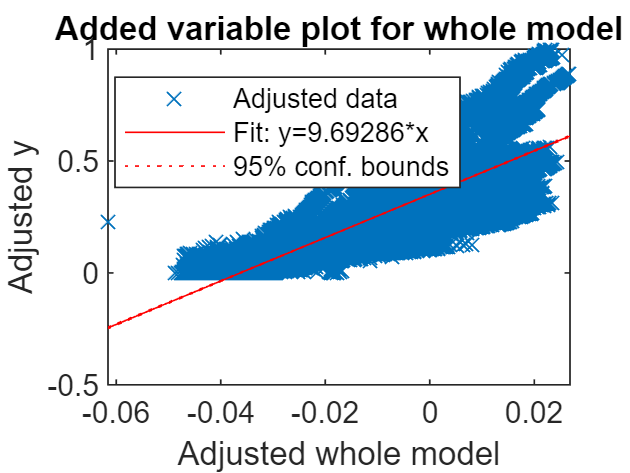

% coeff_IcRul = mdl_Linear_IcRul.Coefficients.Estimate;
% coeff_IcRul'
% x_trainValid_Ic(1,:)
% yhat_trainValid_IcRul = x_trainValid_Ic*coeff_IcRul(2:21)+coeff_IcRul(1);
% yhat_trainValid_IcRul'

% figure
% hold on
% plot(y_trainValid_RUL,yhat_trainValid_IcRul,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'


figure
plot(mdl_Linear_IcRul)

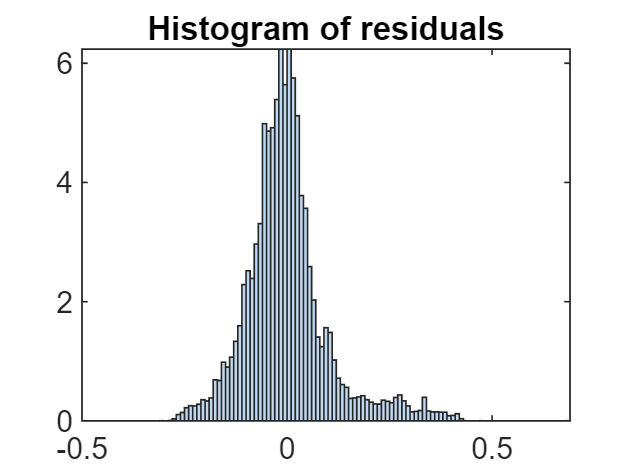

plotResiduals(mdl_Linear_IcRul)


figure
yfit_trainValid_IcRul = predict(mdl_Linear_IcRul,x_trainValid_Ic);
yfit_trainValid_IcRul'

ans =     0.3944    0.4746    0.4746    0.4279    0.4216    0.4623    0.4108    0.4578    0.3835    0.3807    0.4164    0.4518    0.4529    0.3897    0.3786    0.4446    0.4437    0.3617    0.4388    0.4403    0.4446    0.4443    0.3508    0.4399    0.4323    0.4280    0.3462    0.4211    0.3509    0.4191    0.4177    0.4145    0.4118    0.4115    0.3821    0.4085    0.4060    0.4050    0.4034    0.3427    0.3992    0.4185    0.3339    0.3974    0.3864    0.3998    0.3925    0.3171    0.3910    0.3366


yfit_test_IcRul = predict(mdl_Linear_IcRul,x_test_Ic);
yfit_test_IcRul'

ans =     0.3495    0.3424    0.3422    0.3383    0.3366    0.3317    0.3308    0.3289    0.3250    0.3225    0.3202    0.3150    0.3125    0.3120    0.3121    0.3094    0.3066    0.3058    0.3649    0.3620    0.2994    0.3024    0.3043    0.3663    0.3059    0.3052    0.3634    0.2996    0.2956    0.2893    0.2833    0.2793    0.2782    0.2765    0.2742    0.2724    0.2705    0.2689    0.2657    0.2654    0.2616    0.2630    0.2605    0.2583    0.2572    0.2556    0.2546    0.3133    0.2501    0.2492



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274


Yfit_trainValid_IcRul = yfit_trainValid_IcRul * yrate_RUL + ymin_RUL;
Yfit_test_IcRul = yfit_test_IcRul * yrate_RUL + ymin_RUL;

MAE_IcRul = mean(abs(Yfit_trainValid_IcRul-Y_trainValid_RUL))

MAE_IcRul = 83.2595

adjMAE_IcRul = MAE_IcRul/range(Y_trainValid_RUL)

adjMAE_IcRul = 0.0712

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcRul)'    % Errors

ans =   -34.3955 -129.3179 -130.2648  -76.5864  -70.2821 -118.9412  -59.6322 -115.6789  -29.7398  -27.4168  -70.2254 -112.5807 -114.8504  -41.8981  -29.9867 -108.1989 -108.1333  -13.2245 -104.3385 -107.1221 -113.1459 -113.7804   -5.4167 -110.6395 -102.8294  -98.7234   -4.0849  -92.6573  -11.5085  -92.3399  -91.6529  -88.9336  -86.7898  -87.4408  -54.0760  -85.8941  -83.9986  -83.8772  -83.0086  -12.9640  -80.0880 -103.7033   -5.6213  -80.9168  -69.0589  -85.7251  -78.2384    9.0027  -78.5285  -15.8721


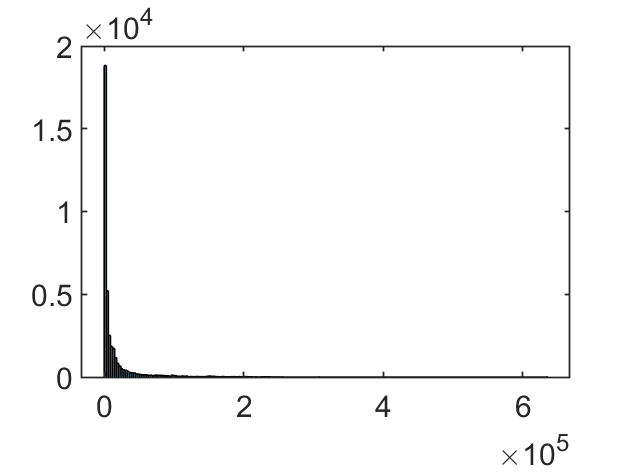

(Y_trainValid_RUL - Yfit_trainValid_IcRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2);   % Mean Squared Error
RMSE_trainValid_IcRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcRul = 119.0894


RMSE_test_IcRul = sqrt(mean((Y_test_RUL - Yfit_test_IcRul).^2))

RMSE_test_IcRul = 123.4953

Y_test_RUL - Yfit_test_IcRul

ans =   -93.8606
  -86.6618
  -87.3212
  -83.8260
  -82.7672
  -78.1325
  -77.9872
  -76.8289
  -73.3083
  -71.3650


Y_test_diff_IcRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul))

Y_test_diff_IcRul = 1.0e+03 *

    0.3160   -0.0939
    0.3150   -0.0867
    0.3140   -0.0873
    0.3130   -0.0838
    0.3120   -0.0828
    0.3110   -0.0781
    0.3100   -0.0780
    0.3090   -0.0768
    0.3080   -0.0733
    0.3070   -0.0714


Y_test_diff_percentage_IcRul = abs(Y_test_RUL-Yfit_test_IcRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcRul = 1.0e+04 *

    0.0030
    0.0028
    0.0028
    0.0027
    0.0027
    0.0025
    0.0025
    0.0025
    0.0024
    0.0023


Y_test_diff_percentage_avg_IcRul = sum(Y_test_diff_percentage_IcRul)/length(Y_test_diff_percentage_IcRul)

Y_test_diff_percentage_avg_IcRul = 94.3030

Y_trainValid_diff_IcRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcRul))

Y_trainValid_diff_IcRul = 1.0e+03 *

    0.4280   -0.0344
    0.4270   -0.1293
    0.4260   -0.1303
    0.4250   -0.0766
    0.4240   -0.0703
    0.4230   -0.1189
    0.4220   -0.0596
    0.4210   -0.1157
    0.4200   -0.0297
    0.4190   -0.0274


Y_trainValid_diff_percentage_IcRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcRul = 1.0e+04 *

    0.0008
    0.0030
    0.0031
    0.0018
    0.0017
    0.0028
    0.0014
    0.0027
    0.0007
    0.0007


Y_trainValid_diff_percentage_avg_IcRul = sum(Y_trainValid_diff_percentage_IcRul)/length(Y_trainValid_diff_percentage_IcRul)

Y_trainValid_diff_percentage_avg_IcRul = 94.0588

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul),Y_test_diff_percentage_IcRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+04 *

    0.0001    0.0316   -0.0094    0.0030
    0.0002    0.0315   -0.0087    0.0028
    0.0003    0.0314   -0.0087    0.0028
    0.0004    0.0313   -0.0084    0.0027
    0.0005    0.0312   -0.0083    0.0027
    0.0006    0.0311   -0.0078    0.0025
    0.0007    0.0310   -0.0078    0.0025
    0.0008    0.0309   -0.0077    0.0025
    0.0009    0.0308   -0.0073    0.0024
    0.0010    0.0307   -0.0071    0.0023


result_mdl_Linear_IcRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul),Y_test_diff_percentage_IcRul);
result_mdl_Linear_IcRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Linear_IcRul

result_mdl_Linear_IcRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -93.861    29.703 
       2       315    -86.662    27.512 
       3       314    -87.321    27.809 
       4       313    -83.826    26.781 
       5       312    -82.767    26.528 
       6       311    -78.132    25.123 
       7       310    -77.987    25.157 
       8       309    -76.829    24.864 
       9       308    -73.308    23.801 
      10       307    -71.365    23.246 
      11       306    -69.668    22.767 
      12       305     -64.58    21.174 
      13       304    -62.586    20.588 
      14       303    -63.047    20.808 
      15       302    -64.213    21.263 
      16       301    -61.966    20.587 


result_mdl_Linear_IcRul_summary = table(RMSE_test_IcRul,Y_test_diff_percentage_avg_IcRul);
result_mdl_Linear_IcRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_IcRul_summary 

result_mdl_Linear_IcRul_summary = 1×2 table
    RMSE     평균오차비율
    _____    __________

    123.5      94.303  


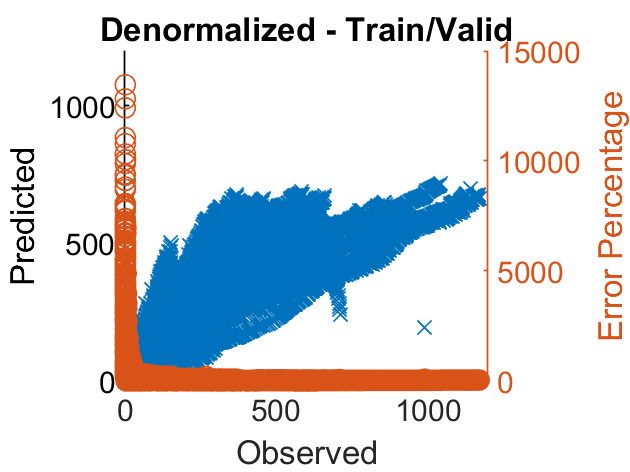


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcRul

RMSE_test_IcRul = 123.4953

Y_trainValid_diff_percentage_avg_IcRul

Y_trainValid_diff_percentage_avg_IcRul = 94.0588

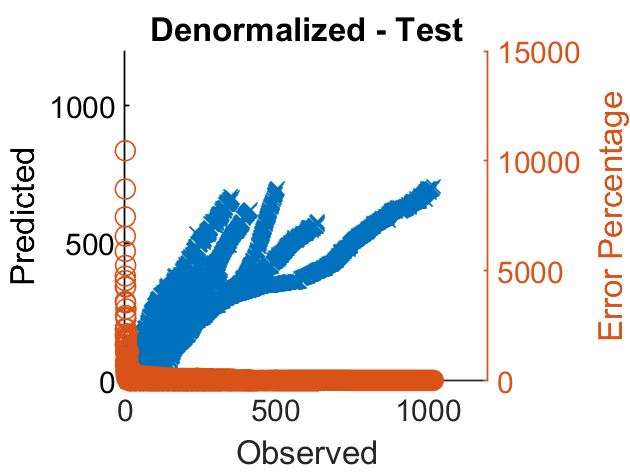


figure
hold on
plot(Y_test_RUL,Yfit_test_IcRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcRul,'o');

hold off
title 'Denormalized - Test'

# 선형회귀 - 예측 - Vd (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

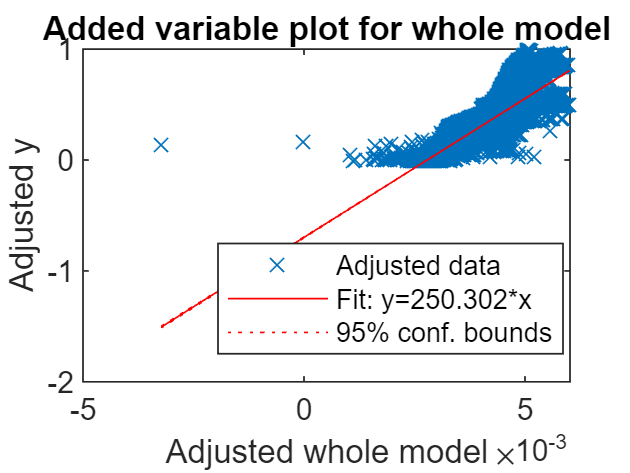

% coeff_VdRul = mdl_Linear_VdRul.Coefficients.Estimate;
% coeff_VdRul'
% x_trainValid_Vd(1,:)
% yhat_trainValid_VdRul = x_trainValid_Vd*coeff_VdRul(2:21)+coeff_VdRul(1);
% yhat_trainValid_VdRul'
% figure
% hold on
% plot(y_trainValid_RUL,yhat_trainValid_VdRul,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'

figure
plot(mdl_Linear_VdRul)

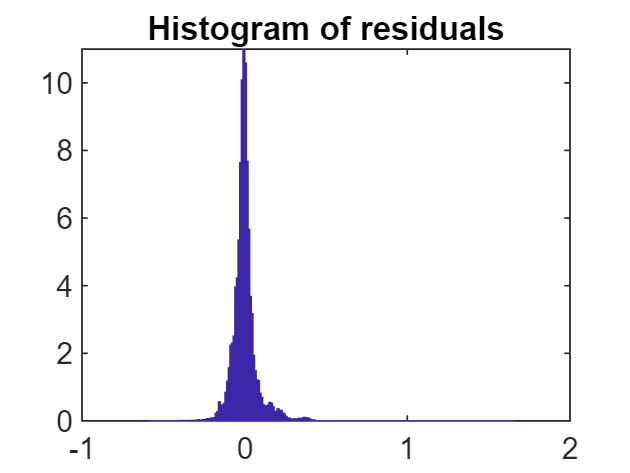

plotResiduals(mdl_Linear_VdRul)

figure
yfit_trainValid_VdRul = predict(mdl_Linear_VdRul,x_trainValid_Vd);
yfit_trainValid_VdRul'

ans =     0.3863    0.3916    0.3881    0.3834    0.3883    0.3876    0.3808    0.3842    0.3728    0.3686    0.3804    0.3810    0.3824    0.3773    0.3713    0.3808    0.3800    0.3697    0.3730    0.3847    0.3904    0.3870    0.3822    0.3760    0.3784    0.3687    0.3675    0.3608    0.3725    0.3696    0.3699    0.3649    0.3669    0.3638    0.3572    0.3629    0.3623    0.3575    0.3589    0.3565    0.3605    0.3585    0.3513    0.3634    0.3555    0.3484    0.3441    0.3517    0.3615    0.3586


yfit_test_VdRul = predict(mdl_Linear_VdRul,x_test_Vd);
yfit_test_VdRul'

ans =     0.3516    0.3560    0.3539    0.3452    0.3379    0.3432    0.3336    0.3482    0.3405    0.3420    0.3311    0.3325    0.3289    0.3368    0.3388    0.3372    0.3252    0.3302    0.3307    0.3128    0.3209    0.3352    0.3535    0.3479    0.3668    0.3612    0.3521    0.3529    0.3354    0.3145    0.2987    0.3072    0.3061    0.2973    0.2941    0.2990    0.3026    0.2921    0.3018    0.2932    0.2918    0.2860    0.2889    0.2832    0.2791    0.2774    0.2816    0.2764    0.2813    0.2875



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274


Yfit_trainValid_VdRul = yfit_trainValid_VdRul * yrate_RUL + ymin_RUL;
Yfit_test_VdRul = yfit_test_VdRul * yrate_RUL + ymin_RUL;

MAE_VdRul = mean(abs(Yfit_trainValid_VdRul-Y_trainValid_RUL))

MAE_VdRul = 55.1521

adjMAE_VdRul = MAE_VdRul/range(Y_trainValid_RUL)

adjMAE_VdRul = 0.0471

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdRul)'    % Errors

ans = 1.0e+03 *

   -0.0250   -0.0322   -0.0290   -0.0246   -0.0313   -0.0315   -0.0246   -0.0295   -0.0171   -0.0132   -0.0281   -0.0297   -0.0324   -0.0274   -0.0214   -0.0335   -0.0336   -0.0225   -0.0274   -0.0421   -0.0498   -0.0468   -0.0422   -0.0359   -0.0397   -0.0293   -0.0290   -0.0221   -0.0368   -0.0345   -0.0358   -0.0309   -0.0343   -0.0317   -0.0249   -0.0326   -0.0328   -0.0282   -0.0309   -0.0291   -0.0348   -0.0335   -0.0260   -0.0411   -0.0329   -0.0257   -0.0216   -0.0315   -0.0439   -0.0416


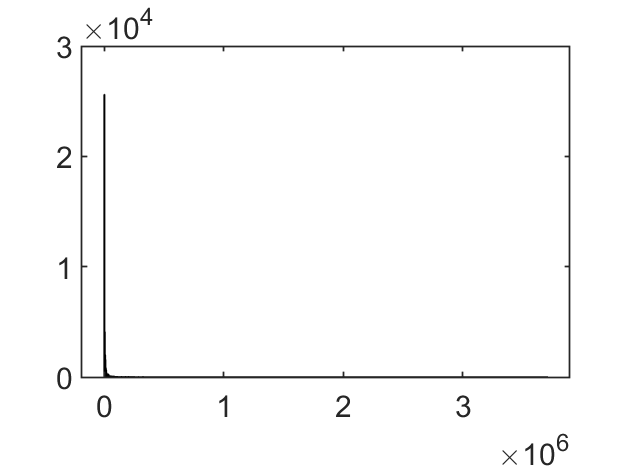

(Y_trainValid_RUL - Yfit_trainValid_VdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2);   % Mean Squared Error
RMSE_trainValid_VdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdRul = 86.5841


RMSE_test_VdRul = sqrt(mean((Y_test_RUL - Yfit_test_VdRul).^2))

RMSE_test_VdRul = 95.0901

Y_test_RUL - Yfit_test_VdRul

ans =   -96.3510
 -102.5264
 -101.0103
  -91.9001
  -84.3768
  -91.5010
  -81.3595
  -99.3610
  -91.3302
  -94.1391


Y_test_diff_VdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul))

Y_test_diff_VdRul = 1.0e+03 *

    0.3160   -0.0964
    0.3150   -0.1025
    0.3140   -0.1010
    0.3130   -0.0919
    0.3120   -0.0844
    0.3110   -0.0915
    0.3100   -0.0814
    0.3090   -0.0994
    0.3080   -0.0913
    0.3070   -0.0941


Y_test_diff_percentage_VdRul = abs(Y_test_RUL-Yfit_test_VdRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdRul = 1.0e+03 *

    0.0305
    0.0325
    0.0322
    0.0294
    0.0270
    0.0294
    0.0262
    0.0322
    0.0297
    0.0307


Y_test_diff_percentage_avg_VdRul = sum(Y_test_diff_percentage_VdRul)/length(Y_test_diff_percentage_VdRul)

Y_test_diff_percentage_avg_VdRul = 57.1944

Y_trainValid_diff_VdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdRul))

Y_trainValid_diff_VdRul = 1.0e+03 *

    0.4280   -0.0250
    0.4270   -0.0322
    0.4260   -0.0290
    0.4250   -0.0246
    0.4240   -0.0313
    0.4230   -0.0315
    0.4220   -0.0246
    0.4210   -0.0295
    0.4200   -0.0171
    0.4190   -0.0132


Y_trainValid_diff_percentage_VdRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdRul = 1.0e+04 *

    0.0006
    0.0008
    0.0007
    0.0006
    0.0007
    0.0007
    0.0006
    0.0007
    0.0004
    0.0003


Y_trainValid_diff_percentage_avg_VdRul = sum(Y_trainValid_diff_percentage_VdRul)/length(Y_trainValid_diff_percentage_VdRul)

Y_trainValid_diff_percentage_avg_VdRul = 60.1664

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul),Y_test_diff_percentage_VdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160   -0.0964    0.0305
    0.0020    0.3150   -0.1025    0.0325
    0.0030    0.3140   -0.1010    0.0322
    0.0040    0.3130   -0.0919    0.0294
    0.0050    0.3120   -0.0844    0.0270
    0.0060    0.3110   -0.0915    0.0294
    0.0070    0.3100   -0.0814    0.0262
    0.0080    0.3090   -0.0994    0.0322
    0.0090    0.3080   -0.0913    0.0297
    0.0100    0.3070   -0.0941    0.0307


result_mdl_Linear_VdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul),Y_test_diff_percentage_VdRul);
result_mdl_Linear_VdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Linear_VdRul

result_mdl_Linear_VdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -96.351    30.491 
       2       315    -102.53    32.548 
       3       314    -101.01    32.169 
       4       313      -91.9    29.361 
       5       312    -84.377    27.044 
       6       311    -91.501    29.422 
       7       310     -81.36    26.245 
       8       309    -99.361    32.156 
       9       308     -91.33    29.653 
      10       307    -94.139    30.664 
      11       306    -82.361    26.915 
      12       305    -84.971    27.859 
      13       304     -81.78    26.901 
      14       303    -92.047    30.378 
      15       302    -95.388    31.585 
      16       301    -94.502    31.396 


result_mdl_Linear_VdRul_summary = table(RMSE_test_VdRul,Y_test_diff_percentage_avg_VdRul);
result_mdl_Linear_VdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_VdRul_summary 

result_mdl_Linear_VdRul_summary = 1×2 table
    RMSE     평균오차비율
    _____    __________

    95.09      57.194  


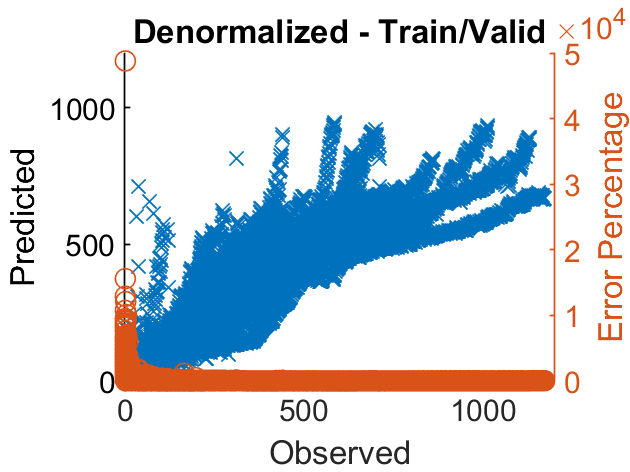


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdRul

RMSE_test_VdRul = 95.0901

Y_trainValid_diff_percentage_avg_VdRul

Y_trainValid_diff_percentage_avg_VdRul = 60.1664

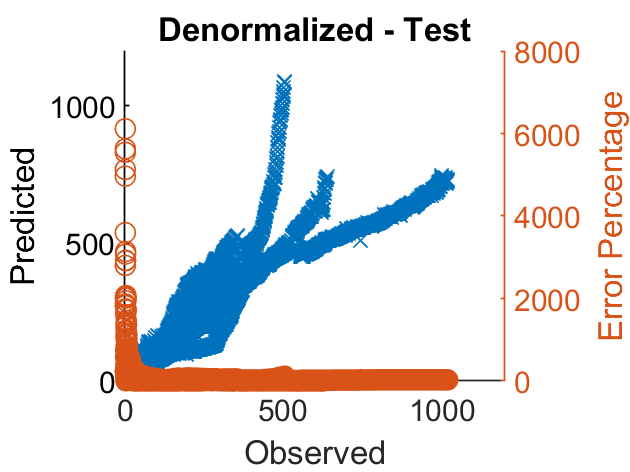


figure
hold on
plot(Y_test_RUL,Yfit_test_VdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_VdRul,'o');

hold off
title 'Denormalized - Test'

# 선형회귀 - 예측 - IcVd (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

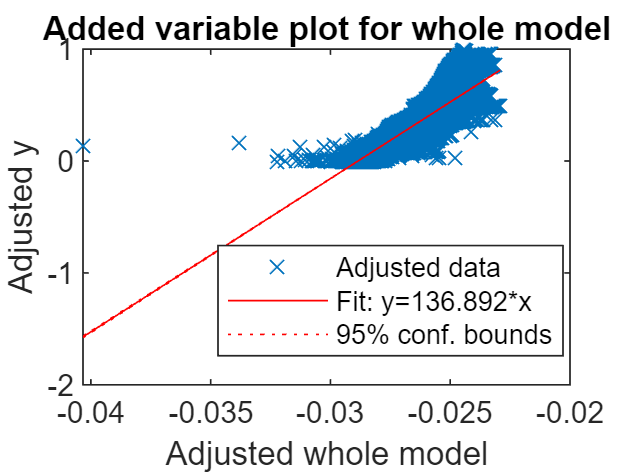

% coeff_IcVdRul = mdl_Linear_IcVdRul.Coefficients.Estimate;
% coeff_IcVdRul'
% x_trainValid_IcVd(1,:)
% yhat_trainValid_IcVdRul = x_trainValid_IcVd*coeff_IcVdRul(2:21)+coeff_IcVdRul(1);
% yhat_trainValid_IcVdRul'
% figure
% hold on
% plot(y_trainValid_RUL,yhat_trainValid_IcVdRul,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'

figure
plot(mdl_Linear_IcVdRul)

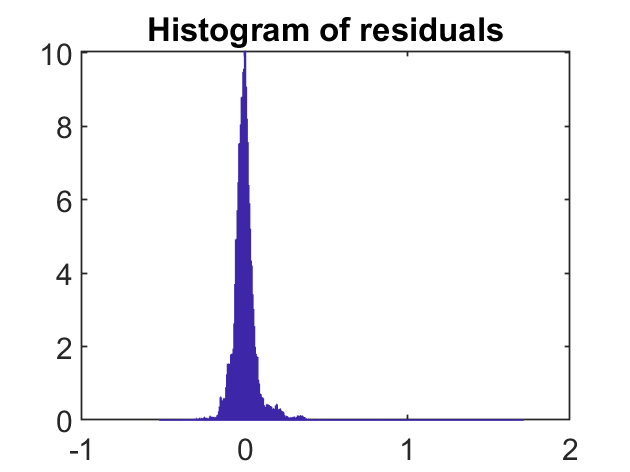

plotResiduals(mdl_Linear_IcVdRul)

figure
yfit_trainValid_IcVdRul = predict(mdl_Linear_IcVdRul,x_trainValid_IcVd);
yfit_trainValid_IcVdRul'

ans =     0.3767    0.3939    0.3892    0.3777    0.3827    0.3884    0.3733    0.3838    0.3624    0.3611    0.3747    0.3811    0.3830    0.3702    0.3618    0.3776    0.3788    0.3587    0.3733    0.3822    0.3885    0.3863    0.3688    0.3766    0.3769    0.3682    0.3586    0.3616    0.3713    0.3667    0.3667    0.3640    0.3656    0.3632    0.3523    0.3641    0.3599    0.3550    0.3557    0.3601    0.3563    0.3856    0.3695    0.3603    0.3752    0.3546    0.3496    0.3383    0.3541    0.3480


yfit_test_IcVdRul = predict(mdl_Linear_IcVdRul,x_test_IcVd);
yfit_test_IcVdRul'

ans =     0.3372    0.3367    0.3330    0.3279    0.3203    0.3235    0.3175    0.3288    0.3213    0.3230    0.3165    0.3127    0.3115    0.3197    0.3217    0.3161    0.3062    0.3114    0.3173    0.3026    0.3042    0.3152    0.3330    0.3381    0.3461    0.3404    0.3420    0.3334    0.3168    0.2966    0.2773    0.2885    0.2879    0.2807    0.2746    0.2775    0.2817    0.2722    0.2814    0.2726    0.2721    0.2655    0.2687    0.2639    0.2586    0.2572    0.2590    0.2637    0.2592    0.2664



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274


Yfit_trainValid_IcVdRul = yfit_trainValid_IcVdRul * yrate_RUL + ymin_RUL;
Yfit_test_IcVdRul = yfit_test_IcVdRul * yrate_RUL + ymin_RUL;

MAE_IcVdRul = mean(abs(Yfit_trainValid_IcVdRul-Y_trainValid_RUL))

MAE_IcVdRul = 53.3657

adjMAE_IcVdRul = MAE_IcVdRul/range(Y_trainValid_RUL)

adjMAE_IcVdRul = 0.0456

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcVdRul)'    % Errors

ans = 1.0e+03 *

   -0.0138   -0.0348   -0.0304   -0.0180   -0.0248   -0.0325   -0.0158   -0.0290   -0.0050   -0.0045   -0.0214   -0.0299   -0.0331   -0.0192   -0.0104   -0.0298   -0.0322   -0.0097   -0.0277   -0.0392   -0.0475   -0.0460   -0.0265   -0.0367   -0.0380   -0.0288   -0.0185   -0.0231   -0.0355   -0.0311   -0.0320   -0.0299   -0.0327   -0.0309   -0.0192   -0.0340   -0.0301   -0.0253   -0.0272   -0.0334   -0.0298   -0.0651   -0.0473   -0.0375   -0.0559   -0.0329   -0.0280   -0.0158   -0.0353   -0.0292


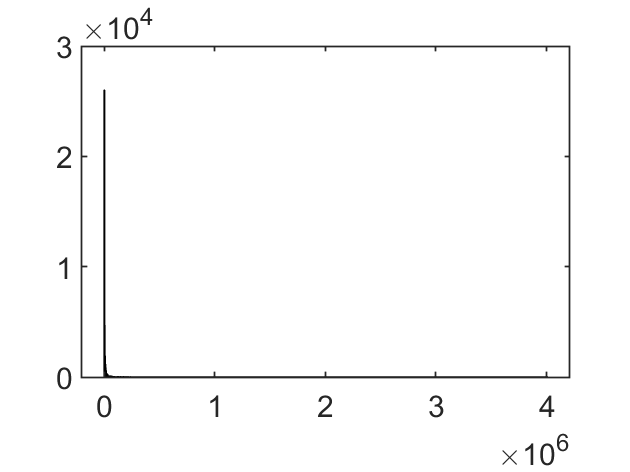

(Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2);   % Mean Squared Error
RMSE_trainValid_IcVdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcVdRul = 81.3242


RMSE_test_IcVdRul = sqrt(mean((Y_test_RUL - Yfit_test_IcVdRul).^2))

RMSE_test_IcVdRul = 94.7969

Y_test_RUL - Yfit_test_IcVdRul

ans =   -79.5384
  -79.9832
  -76.5940
  -71.6472
  -63.7073
  -68.4438
  -62.4183
  -76.6917
  -68.9218
  -71.8559


Y_test_diff_IcVdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul))

Y_test_diff_IcVdRul = 1.0e+03 *

    0.3160   -0.0795
    0.3150   -0.0800
    0.3140   -0.0766
    0.3130   -0.0716
    0.3120   -0.0637
    0.3110   -0.0684
    0.3100   -0.0624
    0.3090   -0.0767
    0.3080   -0.0689
    0.3070   -0.0719


Y_test_diff_percentage_IcVdRul = abs(Y_test_RUL-Yfit_test_IcVdRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcVdRul = 1.0e+03 *

    0.0252
    0.0254
    0.0244
    0.0229
    0.0204
    0.0220
    0.0201
    0.0248
    0.0224
    0.0234


Y_test_diff_percentage_avg_IcVdRul = sum(Y_test_diff_percentage_IcVdRul)/length(Y_test_diff_percentage_IcVdRul)

Y_test_diff_percentage_avg_IcVdRul = 69.1021

Y_trainValid_diff_IcVdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcVdRul))

Y_trainValid_diff_IcVdRul = 1.0e+03 *

    0.4280   -0.0138
    0.4270   -0.0348
    0.4260   -0.0304
    0.4250   -0.0180
    0.4240   -0.0248
    0.4230   -0.0325
    0.4220   -0.0158
    0.4210   -0.0290
    0.4200   -0.0050
    0.4190   -0.0045


Y_trainValid_diff_percentage_IcVdRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcVdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcVdRul = 1.0e+04 *

    0.0003
    0.0008
    0.0007
    0.0004
    0.0006
    0.0008
    0.0004
    0.0007
    0.0001
    0.0001


Y_trainValid_diff_percentage_avg_IcVdRul = sum(Y_trainValid_diff_percentage_IcVdRul)/length(Y_trainValid_diff_percentage_IcVdRul)

Y_trainValid_diff_percentage_avg_IcVdRul = 70.3864

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul),Y_test_diff_percentage_IcVdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160   -0.0795    0.0252
    0.0020    0.3150   -0.0800    0.0254
    0.0030    0.3140   -0.0766    0.0244
    0.0040    0.3130   -0.0716    0.0229
    0.0050    0.3120   -0.0637    0.0204
    0.0060    0.3110   -0.0684    0.0220
    0.0070    0.3100   -0.0624    0.0201
    0.0080    0.3090   -0.0767    0.0248
    0.0090    0.3080   -0.0689    0.0224
    0.0100    0.3070   -0.0719    0.0234


result_mdl_Linear_IcVdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul),Y_test_diff_percentage_IcVdRul);
result_mdl_Linear_IcVdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Linear_IcVdRul

result_mdl_Linear_IcVdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -79.538     25.17 
       2       315    -79.983    25.391 
       3       314    -76.594    24.393 
       4       313    -71.647     22.89 
       5       312    -63.707    20.419 
       6       311    -68.444    22.008 
       7       310    -62.418    20.135 
       8       309    -76.692    24.819 
       9       308    -68.922    22.377 
      10       307    -71.856    23.406 
      11       306    -65.296    21.339 
      12       305    -61.882    20.289 
      13       304    -61.467    20.219 
      14       303    -72.081    23.789 
      15       302     -75.41     24.97 
      16       301    -69.859    23.209 


result_mdl_Linear_IcVdRul_summary = table(RMSE_test_IcVdRul,Y_test_diff_percentage_avg_IcVdRul);
result_mdl_Linear_IcVdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_IcVdRul_summary 

result_mdl_Linear_IcVdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    94.797      69.102  


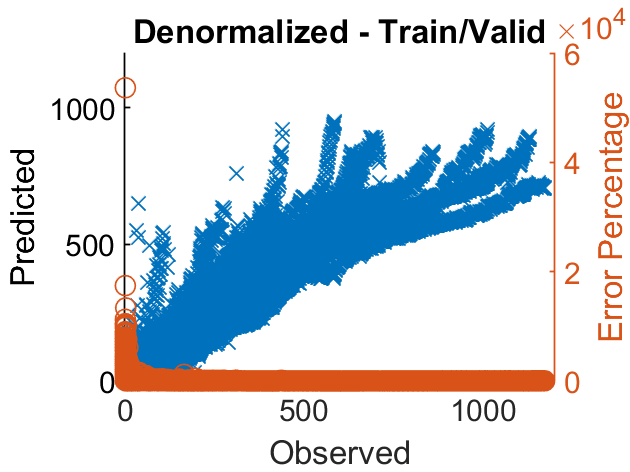


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcVdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcVdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcVdRul

RMSE_test_IcVdRul = 94.7969

Y_trainValid_diff_percentage_avg_IcVdRul

Y_trainValid_diff_percentage_avg_IcVdRul = 70.3864

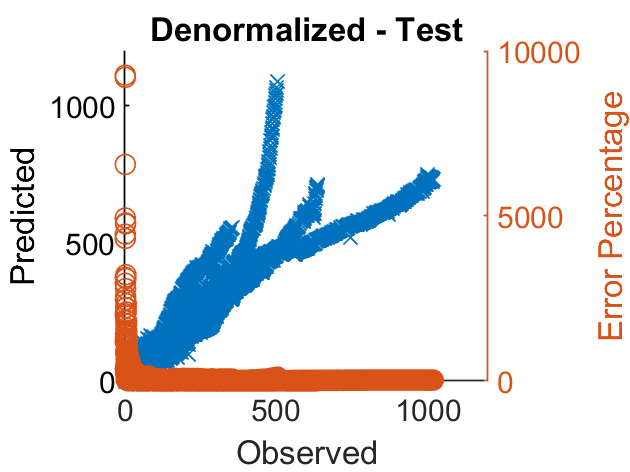


figure
hold on
plot(Y_test_RUL,Yfit_test_IcVdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcVdRul,'o');

hold off
title 'Denormalized - Test'

# 선형회귀 - 예측 - IcVdTd (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

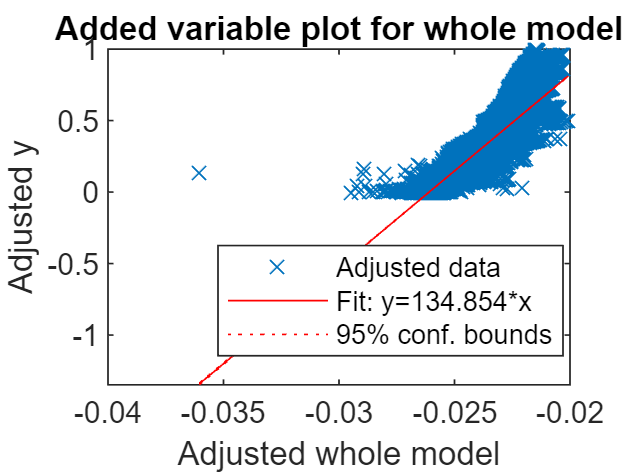

% coeff_IcVdTdRul = mdl_Linear_IcVdTdRul.Coefficients.Estimate;
% coeff_IcVdTdRul'
% x_trainValid_IcVdTd(1,:)
% yhat_trainValid_IcVdTdRul = x_trainValid_IcVdTd*coeff_IcVdTdRul(2:21)+coeff_IcVdTdRul(1);
% yhat_trainValid_IcVdTdRul'
% figure
% hold on
% plot(y_trainValid_RUL,yhat_trainValid_IcVdTdRul,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'

figure
plot(mdl_Linear_IcVdTdRul)

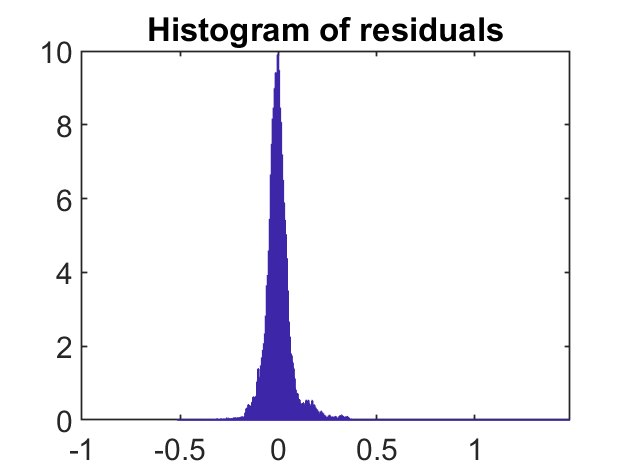

plotResiduals(mdl_Linear_IcVdTdRul)

figure
yfit_trainValid_IcVdTdRul = predict(mdl_Linear_IcVdTdRul,x_trainValid_IcVdTd);
yfit_trainValid_IcVdTdRul'

ans =     0.3811    0.3975    0.3801    0.3749    0.3744    0.3812    0.3615    0.3676    0.3534    0.3418    0.3684    0.3641    0.3607    0.3548    0.3405    0.3514    0.3557    0.3378    0.3309    0.3465    0.3514    0.3408    0.3912    0.3363    0.3294    0.3214    0.3797    0.3782    0.3909    0.3785    0.3773    0.3805    0.3791    0.3758    0.3738    0.3745    0.3717    0.3740    0.3744    0.3718    0.3692    0.3980    0.3880    0.3785    0.3848    0.3720    0.3518    0.3542    0.3675    0.3675


yfit_test_IcVdTdRul = predict(mdl_Linear_IcVdTdRul,x_test_IcVdTd);
yfit_test_IcVdTdRul'

ans =     0.3087    0.3028    0.3018    0.2826    0.2562    0.2630    0.2494    0.2659    0.2520    0.2470    0.2447    0.2122    0.1989    0.2170    0.2228    0.3258    0.3201    0.3171    0.3273    0.3098    0.3173    0.3219    0.3447    0.3487    0.3569    0.3561    0.3494    0.3404    0.3222    0.3070    0.2866    0.2946    0.2990    0.2910    0.2823    0.2807    0.2914    0.2769    0.2824    0.2784    0.2752    0.2637    0.2734    0.2631    0.2606    0.2586    0.2604    0.2649    0.2628    0.2717



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274


Yfit_trainValid_IcVdTdRul = yfit_trainValid_IcVdTdRul * yrate_RUL + ymin_RUL;
Yfit_test_IcVdTdRul = yfit_test_IcVdTdRul * yrate_RUL + ymin_RUL;

MAE_IcVdTdRul = mean(abs(Yfit_trainValid_IcVdTdRul-Y_trainValid_RUL))

MAE_IcVdTdRul = 52.7813

adjMAE_IcVdTdRul = MAE_IcVdTdRul/range(Y_trainValid_RUL)

adjMAE_IcVdTdRul = 0.0451

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul)'    % Errors

ans = 1.0e+03 *

   -0.0189   -0.0390   -0.0197   -0.0146   -0.0151   -0.0239   -0.0020   -0.0100    0.0056    0.0181   -0.0141   -0.0099   -0.0071   -0.0011    0.0146    0.0008   -0.0052    0.0148    0.0218    0.0026   -0.0041    0.0073   -0.0527    0.0106    0.0177    0.0260   -0.0433   -0.0425   -0.0583   -0.0448   -0.0444   -0.0492   -0.0485   -0.0457   -0.0443   -0.0461   -0.0438   -0.0476   -0.0490   -0.0470   -0.0450   -0.0797   -0.0690   -0.0588   -0.0672   -0.0533   -0.0306   -0.0344   -0.0510   -0.0519


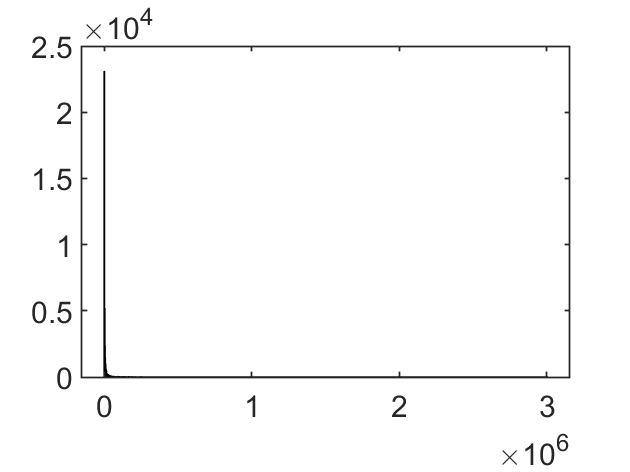

(Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2);   % Mean Squared Error
RMSE_trainValid_IcVdTdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcVdTdRul = 79.7039


RMSE_test_IcVdTdRul = sqrt(mean((Y_test_RUL - Yfit_test_IcVdTdRul).^2))

RMSE_test_IcVdTdRul = 92.4311

Y_test_RUL - Yfit_test_IcVdTdRul

ans =   -46.1672
  -40.3199
  -40.1143
  -18.5981
   11.2770
    2.2412
   17.2128
   -3.1101
   12.1514
   16.9670


Y_test_diff_IcVdTdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul))

Y_test_diff_IcVdTdRul = 1.0e+03 *

    0.3160   -0.0462
    0.3150   -0.0403
    0.3140   -0.0401
    0.3130   -0.0186
    0.3120    0.0113
    0.3110    0.0022
    0.3100    0.0172
    0.3090   -0.0031
    0.3080    0.0122
    0.3070    0.0170


Y_test_diff_percentage_IcVdTdRul = abs(Y_test_RUL-Yfit_test_IcVdTdRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcVdTdRul = 1.0e+04 *

    0.0015
    0.0013
    0.0013
    0.0006
    0.0004
    0.0001
    0.0006
    0.0001
    0.0004
    0.0006


Y_test_diff_percentage_avg_IcVdTdRul = sum(Y_test_diff_percentage_IcVdTdRul)/length(Y_test_diff_percentage_IcVdTdRul)

Y_test_diff_percentage_avg_IcVdTdRul = 70.1835

Y_trainValid_diff_IcVdTdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcVdTdRul))

Y_trainValid_diff_IcVdTdRul = 1.0e+03 *

    0.4280   -0.0189
    0.4270   -0.0390
    0.4260   -0.0197
    0.4250   -0.0146
    0.4240   -0.0151
    0.4230   -0.0239
    0.4220   -0.0020
    0.4210   -0.0100
    0.4200    0.0056
    0.4190    0.0181


Y_trainValid_diff_percentage_IcVdTdRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcVdTdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcVdTdRul = 1.0e+04 *

    0.0004
    0.0009
    0.0005
    0.0003
    0.0004
    0.0006
    0.0000
    0.0002
    0.0001
    0.0004


Y_trainValid_diff_percentage_avg_IcVdTdRul = sum(Y_trainValid_diff_percentage_IcVdTdRul)/length(Y_trainValid_diff_percentage_IcVdTdRul)

Y_trainValid_diff_percentage_avg_IcVdTdRul = 70.3242

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul),Y_test_diff_percentage_IcVdTdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+04 *

    0.0001    0.0316   -0.0046    0.0015
    0.0002    0.0315   -0.0040    0.0013
    0.0003    0.0314   -0.0040    0.0013
    0.0004    0.0313   -0.0019    0.0006
    0.0005    0.0312    0.0011    0.0004
    0.0006    0.0311    0.0002    0.0001
    0.0007    0.0310    0.0017    0.0006
    0.0008    0.0309   -0.0003    0.0001
    0.0009    0.0308    0.0012    0.0004
    0.0010    0.0307    0.0017    0.0006


result_mdl_Linear_IcVdTdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul),Y_test_diff_percentage_IcVdTdRul);
result_mdl_Linear_IcVdTdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Linear_IcVdTdRul

result_mdl_Linear_IcVdTdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -46.167      14.61
       2       315     -40.32       12.8
       3       314    -40.114     12.775
       4       313    -18.598     5.9419
       5       312     11.277     3.6144
       6       311     2.2412    0.72063
       7       310     17.213     5.5525
       8       309    -3.1101     1.0065
       9       308     12.151     3.9452
      10       307     16.967     5.5267
      11       306     18.661     6.0983
      12       305     55.783     18.289
      13       304     70.284      23.12
      14       303      48.14     15.888
      15       302     40.309     13.347
      16       301      -81.2     26.977


result_mdl_Linear_IcVdTdRul_summary = table(RMSE_test_IcVdTdRul,Y_test_diff_percentage_avg_IcVdTdRul);
result_mdl_Linear_IcVdTdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_IcVdTdRul_summary 

result_mdl_Linear_IcVdTdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    92.431      70.184  


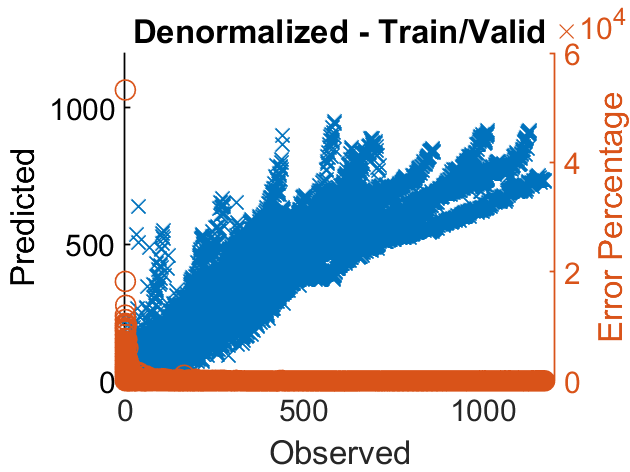


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcVdTdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcVdTdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcVdTdRul

RMSE_test_IcVdTdRul = 92.4311

Y_trainValid_diff_percentage_avg_IcVdTdRul

Y_trainValid_diff_percentage_avg_IcVdTdRul = 70.3242

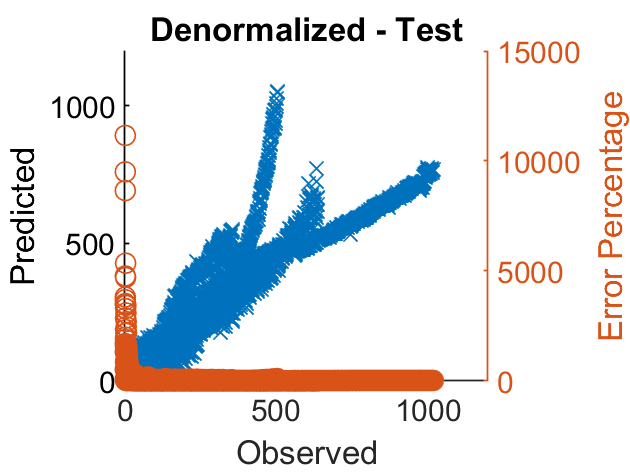


figure
hold on
plot(Y_test_RUL,Yfit_test_IcVdTdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcVdTdRul,'o');

hold off
title 'Denormalized - Test'

# FNN 모델 생성 - 신형회귀와 동일한 20개 뉴런

# FNN 모델 생성 - 3개 layer로 더 deep하게 -  40 20 10개 뉴런

if generate_model
    mdl_Fnn_IcRul = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_IcRul.divideFcn = 'divideind';
    mdl_Fnn_IcRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_IcRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_IcRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_IcRul.trainParam.showWindow = 0; 
    mdl_Fnn_IcRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_IcRul ] = train(mdl_Fnn_IcRul, xnorm_Ic', ynorm_RUL', 'useparallel',  'yes');
    toc

    mdl_Fnn_VdRul = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_VdRul.divideFcn = 'divideind';
    mdl_Fnn_VdRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_VdRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_VdRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_VdRul.trainParam.showWindow = 0; 
    mdl_Fnn_VdRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_VdRul ] = train(mdl_Fnn_VdRul, xnorm_Vd', ynorm_RUL', 'useparallel',  'yes');
    toc
    
    mdl_Fnn_IcVdRul = feedforwardnet(fnn_neuron_layer2); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_IcVdRul.divideFcn = 'divideind';
    mdl_Fnn_IcVdRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_IcVdRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_IcVdRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_IcVdRul.trainParam.showWindow = 0; 
    mdl_Fnn_IcVdRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_IcVdRul ] = train(mdl_Fnn_IcVdRul, xnorm_IcVd', ynorm_RUL', 'useparallel',  'yes');
    toc

    save('ryan4_model_RUL.mat','mdl_Fnn_IcRul' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Fnn_VdRul' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Fnn_IcVdRul' ,'-append')

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 1.887676 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 2.229383 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 24.001986 seconds.


Error using save
Variable 'mdl_Fnn_VdRul_fitrlinear' not found.

    

    mdl_Fnn3_IcRul = feedforwardnet(fnn_neuron_3layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_IcRul.divideFcn = 'divideind';
    mdl_Fnn3_IcRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_IcRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_IcRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_IcRul.trainParam.showWindow = 0; 
    mdl_Fnn3_IcRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_IcRul ] = train(mdl_Fnn3_IcRul, xnorm_Ic', ynorm_RUL', 'useparallel',  'yes');
    toc

    mdl_Fnn3_VdRul = feedforwardnet(fnn_neuron_3layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_VdRul.divideFcn = 'divideind';
    mdl_Fnn3_VdRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_VdRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_VdRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_VdRul.trainParam.showWindow = 0; 
    mdl_Fnn3_VdRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_VdRul ] = train(mdl_Fnn3_VdRul, xnorm_Vd', ynorm_RUL', 'useparallel',  'yes');
    toc

    save('ryan4_model_RUL.mat','mdl_Fnn3_IcRul' ,'-append')
    save('ryan4_model_RUL.mat','mdl_Fnn3_VdRul' ,'-append')
   
end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 33.521270 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 43.202495 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


	
if generate_model
% 시간이 엄청 오래 걸린다.
    mdl_Fnn_IcVdTdRul = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_IcVdTdRul.divideFcn = 'divideind';
    mdl_Fnn_IcVdTdRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_IcVdTdRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_IcVdTdRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_IcVdTdRul.trainParam.showWindow = 0; 
    mdl_Fnn_IcVdTdRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_IcVdTdRul ] = train(mdl_Fnn_IcVdTdRul, xnorm_IcVdTd', ynorm_RUL', 'useparallel',  'yes');
    toc
 
    save('ryan4_model_RUL.mat','mdl_Fnn_IcVdTdRul' ,'-append')
	
    mdl_Fnn3_IcVdRul = feedforwardnet(fnn_neuron_3layer2); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_IcVdRul.divideFcn = 'divideind';
    mdl_Fnn3_IcVdRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_IcVdRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_IcVdRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_IcVdRul.trainParam.showWindow = 0; 
    mdl_Fnn3_IcVdRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_IcVdRul ] = train(mdl_Fnn3_IcVdRul, xnorm_IcVd', ynorm_RUL', 'useparallel',  'yes');
    toc
    save('ryan4_model_RUL.mat','mdl_Fnn3_IcVdRul' ,'-append') 

    mdl_Fnn3_IcVdTdRul = feedforwardnet(fnn_neuron_3layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_IcVdTdRul.divideFcn = 'divideind';
    mdl_Fnn3_IcVdTdRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_IcVdTdRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_IcVdTdRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_IcVdTdRul.trainParam.showWindow = 0; 
    mdl_Fnn3_IcVdTdRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_IcVdTdRul ] = train(mdl_Fnn3_IcVdTdRul, xnorm_IcVdTd', ynorm_RUL', 'useparallel',  'yes');
    toc    

    save('ryan4_model_RUL.mat','mdl_Fnn3_IcVdTdRul' ,'-append')
end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 175.404471 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 784.535263 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 4073.768225 seconds.


# Fnn Ic_RUL

yfit_trainValid_IcRul = mdl_Fnn_IcRul(xnorm_Ic([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_IcRul'

ans =     0.4488    0.5826    0.5820    0.5090    0.4987    0.5680    0.4827    0.5621    0.4408    0.4378    0.4980    0.5560    0.5578    0.4557    0.4376    0.5478    0.5467    0.4124    0.5410    0.5432    0.5491    0.5479    0.3965    0.5440    0.5347    0.5292    0.3959    0.5202    0.4064    0.5179    0.5164    0.5125    0.5092    0.5089    0.4605    0.5063    0.5024    0.5014    0.4997    0.4022    0.4943    0.5310    0.3916    0.4922    0.4783    0.4985    0.4865    0.3618    0.4854    0.3946


yfit_test_IcRul = mdl_Fnn_IcRul(xnorm_Ic( idxTestAll, :)')';
yfit_test_IcRul'

ans =     0.3463    0.3407    0.3405    0.3374    0.3359    0.3320    0.3313    0.3296    0.3265    0.3245    0.3227    0.3182    0.3161    0.3157    0.3158    0.3135    0.3112    0.3105    0.3471    0.3449    0.3050    0.3077    0.3091    0.3483    0.3105    0.3098    0.3460    0.3052    0.3018    0.2965    0.2914    0.2881    0.2871    0.2857    0.2837    0.2822    0.2805    0.2791    0.2764    0.2762    0.2728    0.2740    0.2718    0.2700    0.2690    0.2676    0.2668    0.3045    0.2627    0.2619



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_IcRul = yfit_trainValid_IcRul * yrate_RUL + ymin_RUL;
Yfit_test_IcRul = yfit_test_IcRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Ic_RUL * yrate_Ic_RUL + ymin_Ic_RUL;


MAE_IcRul = mean(abs(Yfit_trainValid_IcRul-Y_trainValid_RUL))

MAE_IcRul = 67.5552

adjMAE_IcRul = MAE_IcRul/range(Y_trainValid_RUL)

adjMAE_IcRul = 0.0577

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcRul)'    % Errors

ans = 1.0e+03 *

   -0.0981   -0.2556   -0.2559   -0.1715   -0.1605   -0.2426   -0.1438   -0.2377   -0.0968   -0.0942   -0.1656   -0.2345   -0.2376   -0.1192   -0.0990   -0.2289   -0.2286   -0.0725   -0.2240   -0.2276   -0.2355   -0.2350   -0.0589   -0.2325   -0.2226   -0.2171   -0.0622   -0.2086   -0.0765   -0.2080   -0.2072   -0.2037   -0.2008   -0.2014   -0.1458   -0.2003   -0.1968   -0.1966   -0.1956   -0.0825   -0.1914   -0.2353   -0.0732   -0.1919   -0.1766   -0.2012   -0.1882   -0.0434   -0.1889   -0.0836


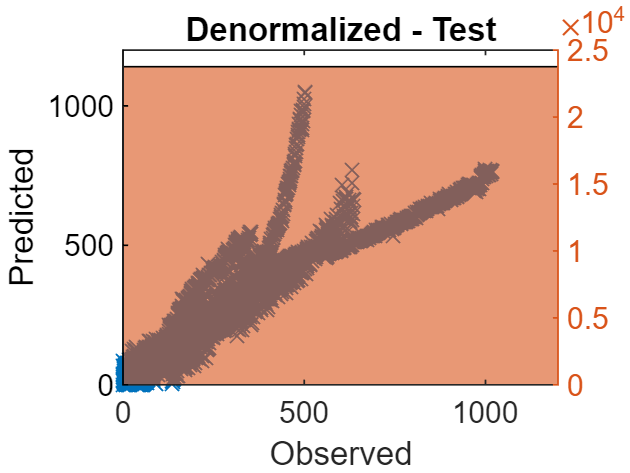

(Y_trainValid_RUL - Yfit_trainValid_IcRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2);   % Mean Squared Error
RMSE_trainValid_IcRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcRul = 105.1450


RMSE_test_IcRul = sqrt(mean((Y_test_RUL - Yfit_test_IcRul).^2))

RMSE_test_IcRul = 95.2188

Y_test_RUL - Yfit_test_IcRul

ans =   -90.1945
  -84.6300
  -85.4385
  -82.7566
  -82.0299
  -78.4826
  -78.5878
  -77.6804
  -75.0024
  -73.6601


Y_test_diff_IcRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul))

Y_test_diff_IcRul = 1.0e+03 *

    0.3160   -0.0902
    0.3150   -0.0846
    0.3140   -0.0854
    0.3130   -0.0828
    0.3120   -0.0820
    0.3110   -0.0785
    0.3100   -0.0786
    0.3090   -0.0777
    0.3080   -0.0750
    0.3070   -0.0737


Y_test_diff_percentage_IcRul = abs(Y_test_RUL-Yfit_test_IcRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcRul = 1.0e+03 *

    0.0285
    0.0269
    0.0272
    0.0264
    0.0263
    0.0252
    0.0254
    0.0251
    0.0244
    0.0240


Y_test_diff_percentage_avg_IcRul = sum(Y_test_diff_percentage_IcRul)/length(Y_test_diff_percentage_IcRul)

Y_test_diff_percentage_avg_IcRul = 53.2731

Y_trainValid_diff_IcRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcRul))

Y_trainValid_diff_IcRul = 1.0e+03 *

    0.4280   -0.0981
    0.4270   -0.2556
    0.4260   -0.2559
    0.4250   -0.1715
    0.4240   -0.1605
    0.4230   -0.2426
    0.4220   -0.1438
    0.4210   -0.2377
    0.4200   -0.0968
    0.4190   -0.0942


Y_trainValid_diff_percentage_IcRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcRul = 1.0e+04 *

    0.0023
    0.0060
    0.0060
    0.0040
    0.0038
    0.0057
    0.0034
    0.0056
    0.0023
    0.0022


Y_trainValid_diff_percentage_avg_IcRul = sum(Y_trainValid_diff_percentage_IcRul)/length(Y_trainValid_diff_percentage_IcRul)

Y_trainValid_diff_percentage_avg_IcRul = 45.8201

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul),Y_test_diff_percentage_IcRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160   -0.0902    0.0285
    0.0020    0.3150   -0.0846    0.0269
    0.0030    0.3140   -0.0854    0.0272
    0.0040    0.3130   -0.0828    0.0264
    0.0050    0.3120   -0.0820    0.0263
    0.0060    0.3110   -0.0785    0.0252
    0.0070    0.3100   -0.0786    0.0254
    0.0080    0.3090   -0.0777    0.0251
    0.0090    0.3080   -0.0750    0.0244
    0.0100    0.3070   -0.0737    0.0240


result_mdl_Fnn_IcRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul),Y_test_diff_percentage_IcRul);
result_mdl_Fnn_IcRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn_IcRul

result_mdl_Fnn_IcRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -90.195    28.543 
       2       315     -84.63    26.867 
       3       314    -85.439     27.21 
       4       313    -82.757     26.44 
       5       312     -82.03    26.292 
       6       311    -78.483    25.236 
       7       310    -78.588    25.351 
       8       309     -77.68    25.139 
       9       308    -75.002    24.351 
      10       307     -73.66    23.994 
      11       306     -72.51    23.696 
      12       305    -68.321      22.4 
      13       304     -66.88        22 
      14       303     -67.38    22.238 
      15       302    -68.482    22.676 
      16       301    -66.804    22.194 


result_mdl_Fnn_IcRul_summary = table(RMSE_test_IcRul,Y_test_diff_percentage_avg_IcRul);
result_mdl_Fnn_IcRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_IcRul_summary 

result_mdl_Fnn_IcRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    95.219      53.273  


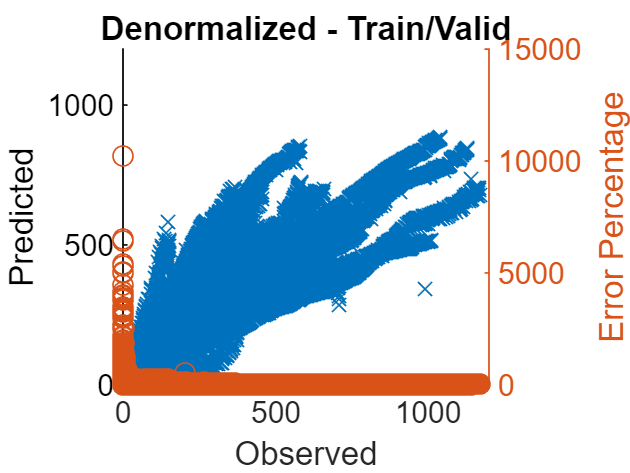


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcRul

RMSE_test_IcRul = 95.2188

Y_trainValid_diff_percentage_avg_IcRul

Y_trainValid_diff_percentage_avg_IcRul = 45.8201

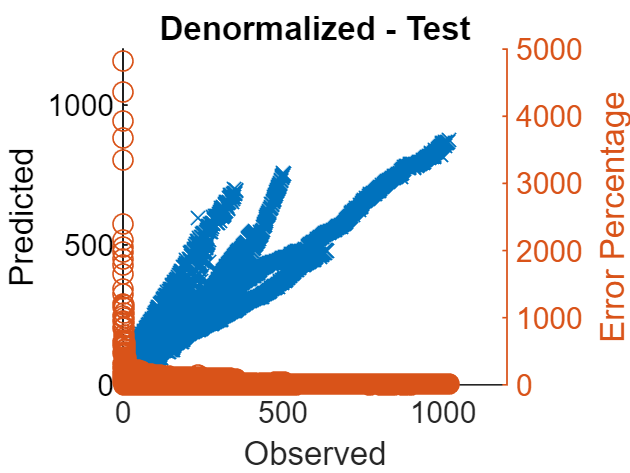


figure
hold on
plot(Y_test_RUL,Yfit_test_IcRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcRul,'o');

hold off
title 'Denormalized - Test'

# Fnn Vd_RUL

yfit_trainValid_VdRul = mdl_Fnn_VdRul(xnorm_Vd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_VdRul'

ans =     0.4010    0.4021    0.3981    0.3973    0.4009    0.3995    0.3954    0.3947    0.3929    0.3923    0.3934    0.3972    0.3957    0.3932    0.3916    0.3927    0.3924    0.3889    0.3912    0.3973    0.4045    0.4036    0.4003    0.3978    0.3939    0.3925    0.3860    0.3837    0.3857    0.3844    0.3836    0.3819    0.3820    0.3836    0.3796    0.3802    0.3791    0.3758    0.3772    0.3746    0.3740    0.3753    0.3751    0.3778    0.3758    0.3709    0.3696    0.3700    0.3748    0.3778


yfit_test_VdRul = mdl_Fnn_VdRul(xnorm_Vd( idxTestAll, :)')';
yfit_test_VdRul'

ans =     0.3847    0.3814    0.3798    0.3767    0.3756    0.3744    0.3733    0.3738    0.3713    0.3707    0.3700    0.3678    0.3668    0.3735    0.3741    0.3654    0.3626    0.3616    0.3608    0.3568    0.3643    0.3776    0.3901    0.3956    0.4008    0.4012    0.4005    0.3995    0.3833    0.3606    0.3464    0.3488    0.3481    0.3460    0.3431    0.3409    0.3417    0.3385    0.3380    0.3364    0.3349    0.3333    0.3356    0.3340    0.3308    0.3298    0.3294    0.3269    0.3281    0.3340



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_VdRul = yfit_trainValid_VdRul * yrate_RUL + ymin_RUL;
Yfit_test_VdRul = yfit_test_VdRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Vd_RUL * yrate_Vd_RUL + ymin_Vd_RUL;


MAE_VdRul = mean(abs(Yfit_trainValid_VdRul-Y_trainValid_RUL))

MAE_VdRul = 87.6284

adjMAE_VdRul = MAE_VdRul/range(Y_trainValid_RUL)

adjMAE_VdRul = 0.0749

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdRul)'    % Errors

ans =   -42.1413  -44.4758  -40.7377  -40.8992  -46.0729  -45.4621  -41.5711  -41.7883  -40.6383  -40.9989  -43.3155  -48.7313  -47.9777  -46.0980  -45.1884  -47.4602  -48.1336  -45.0228  -48.6934  -56.8601  -66.2349  -66.2549  -63.3946  -61.4097  -57.8551  -57.1681  -50.5688  -48.8799  -52.3161  -51.7565  -51.8118  -50.8651  -51.9825  -54.8585  -51.1828  -52.7909  -52.5008  -49.7440  -52.2907  -50.2839  -50.5589  -53.0755  -53.8710  -58.0099  -56.6721  -51.9590  -51.4758  -52.8686  -59.5387  -64.0025


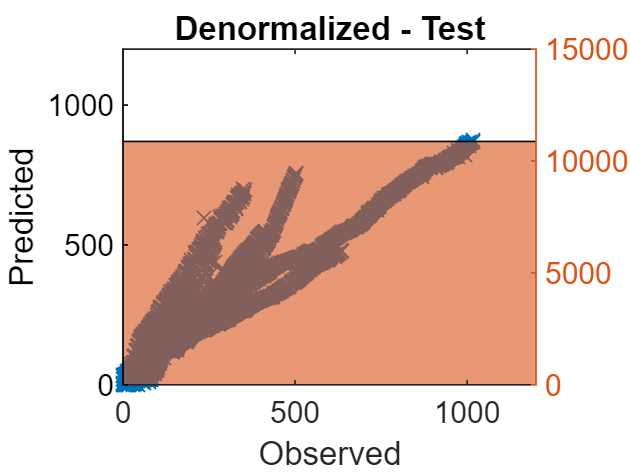

(Y_trainValid_RUL - Yfit_trainValid_VdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2);   % Mean Squared Error
RMSE_trainValid_VdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdRul = 107.6271


RMSE_test_VdRul = sqrt(mean((Y_test_RUL - Yfit_test_VdRul).^2))

RMSE_test_VdRul = 110.0549

Y_test_RUL - Yfit_test_VdRul

ans =  -135.0459
 -132.2281
 -131.3436
 -128.7377
 -128.4760
 -128.0829
 -127.7079
 -129.3094
 -127.4540
 -127.7377


Y_test_diff_VdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul))

Y_test_diff_VdRul = 1.0e+03 *

    0.3160   -0.1350
    0.3150   -0.1322
    0.3140   -0.1313
    0.3130   -0.1287
    0.3120   -0.1285
    0.3110   -0.1281
    0.3100   -0.1277
    0.3090   -0.1293
    0.3080   -0.1275
    0.3070   -0.1277


Y_test_diff_percentage_VdRul = abs(Y_test_RUL-Yfit_test_VdRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdRul = 1.0e+03 *

    0.0427
    0.0420
    0.0418
    0.0411
    0.0412
    0.0412
    0.0412
    0.0418
    0.0414
    0.0416


Y_test_diff_percentage_avg_VdRul = sum(Y_test_diff_percentage_VdRul)/length(Y_test_diff_percentage_VdRul)

Y_test_diff_percentage_avg_VdRul = 63.4471

Y_trainValid_diff_VdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdRul))

Y_trainValid_diff_VdRul = 1.0e+03 *

    0.4280   -0.0421
    0.4270   -0.0445
    0.4260   -0.0407
    0.4250   -0.0409
    0.4240   -0.0461
    0.4230   -0.0455
    0.4220   -0.0416
    0.4210   -0.0418
    0.4200   -0.0406
    0.4190   -0.0410


Y_trainValid_diff_percentage_VdRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdRul = 1.0e+04 *

    0.0010
    0.0010
    0.0010
    0.0010
    0.0011
    0.0011
    0.0010
    0.0010
    0.0010
    0.0010


Y_trainValid_diff_percentage_avg_VdRul = sum(Y_trainValid_diff_percentage_VdRul)/length(Y_trainValid_diff_percentage_VdRul)

Y_trainValid_diff_percentage_avg_VdRul = 71.9048

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul),Y_test_diff_percentage_VdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160   -0.1350    0.0427
    0.0020    0.3150   -0.1322    0.0420
    0.0030    0.3140   -0.1313    0.0418
    0.0040    0.3130   -0.1287    0.0411
    0.0050    0.3120   -0.1285    0.0412
    0.0060    0.3110   -0.1281    0.0412
    0.0070    0.3100   -0.1277    0.0412
    0.0080    0.3090   -0.1293    0.0418
    0.0090    0.3080   -0.1275    0.0414
    0.0100    0.3070   -0.1277    0.0416


result_mdl_Fnn_VdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul),Y_test_diff_percentage_VdRul);
result_mdl_Fnn_VdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn_VdRul

result_mdl_Fnn_VdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -135.05    42.736 
       2       315    -132.23    41.977 
       3       314    -131.34    41.829 
       4       313    -128.74     41.13 
       5       312    -128.48    41.178 
       6       311    -128.08    41.184 
       7       310    -127.71    41.196 
       8       309    -129.31    41.848 
       9       308    -127.45    41.381 
      10       307    -127.74    41.608 
      11       306    -127.91    41.799 
      12       305    -126.28    41.403 
      13       304     -126.1    41.481 
      14       303    -135.03    44.564 
      15       302    -136.75    45.281 
      16       301    -127.57    42.383 


result_mdl_Fnn_VdRul_summary = table(RMSE_test_VdRul,Y_test_diff_percentage_avg_VdRul);
result_mdl_Fnn_VdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_VdRul_summary 

result_mdl_Fnn_VdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    110.05      63.447  


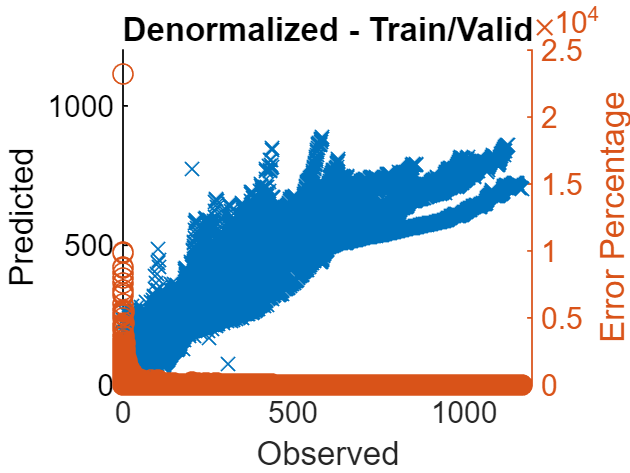


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdRul

RMSE_test_VdRul = 110.0549

Y_trainValid_diff_percentage_avg_VdRul

Y_trainValid_diff_percentage_avg_VdRul = 71.9048

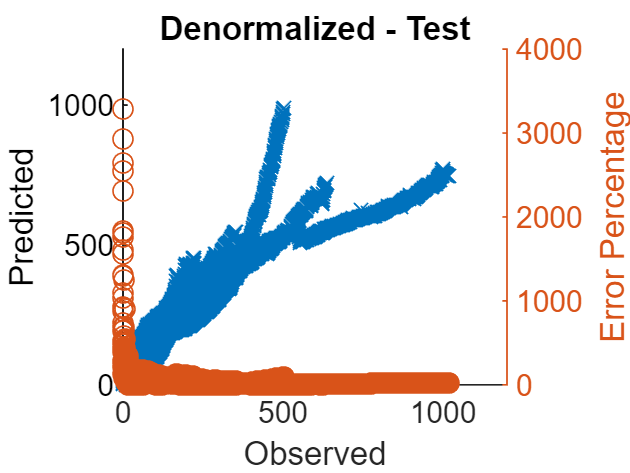


figure
hold on
plot(Y_test_RUL,Yfit_test_VdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_VdRul,'o');

hold off
title 'Denormalized - Test'

mdl_Fnn_VdRul

mdl_Fnn_VdRul =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 441
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

% https://kr.mathworks.com/help/matlab/ref/celldisp.html
cell2mat(mdl_Fnn_VdRul.IW(1,1))

ans =     0.1066   -0.2196    0.1243   -0.2810   -0.0214    0.4952   -0.0219    0.3881    0.1897    0.3009   -0.3834   -0.6838    0.3987   -0.1370    0.3735   -0.1392   -0.3076   -0.0036    0.6800    0.5793
    0.2061    0.0739    0.1584    0.4611    0.2985    0.1080   -0.2561    0.2142   -0.3896   -0.3740   -0.5433    0.0774   -0.0703   -0.6907   -0.4606   -0.4857   -0.8168   -0.3923    0.3032    0.2810
   -0.0085   -0.5478    0.3201   -0.0816   -0.1724   -0.0617   -0.6338    0.3871    0.1084   -0.2796   -0.0945    0.0254   -0.2818   -0.4060   -0.6862    0.4696   -0.4105    0.2938   -0.0951   -0.1004
   -0.1307    0.0174   -0.3434   -0.4952   -0.4460   -0.1438    0.1883   -0.3560    0.3330   -0.1440   -0.2929    0.6645    0.7635   -0.1416    0.0993   -0.0490    0.7036   -0.1542   -0.1532    0.0359
    0.1015    0.5648    0.0093   -0.2018    0.2278   -0.5250   -0.2299    0.4400   -0.1304   -0.1838   -0.0919   -0.6629   -0.0388   -0.4030    0.0515   -0.5594    0.1235    0.5343    0.0057

cell2mat(mdl_Fnn_VdRul.LW(2,1))

ans =    -0.7270    0.5523    0.3805    0.2166    0.7261   -0.1009   -0.5223    0.5510    0.8750   -0.7674    0.0613    0.0089   -0.6281    0.6871   -0.2239   -0.8705   -0.6044    0.1529   -0.3164   -0.3624


cell2mat(mdl_Fnn_VdRul.b(1,1))

ans =    -1.7199
   -1.4834
   -1.3324
    1.1267
   -0.9581
   -0.7520
   -0.5950
    0.3821
   -0.4027
    0.0292


# Fnn IcVd_RUL

yfit_trainValid_IcVdRul = mdl_Fnn_IcVdRul(xnorm_IcVd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_IcVdRul'

ans =     0.4549    0.4733    0.4723    0.4591    0.4611    0.4683    0.4541    0.4625    0.4437    0.4436    0.4518    0.4640    0.4631    0.4448    0.4407    0.4574    0.4571    0.4347    0.4549    0.4615    0.4715    0.4724    0.4455    0.4642    0.4586    0.4528    0.4319    0.4456    0.4449    0.4459    0.4437    0.4423    0.4409    0.4418    0.4330    0.4423    0.4364    0.4347    0.4348    0.4373    0.4297    0.4740    0.4511    0.4326    0.4604    0.4388    0.4240    0.4044    0.4291    0.4191


yfit_test_IcVdRul = mdl_Fnn_IcVdRul(xnorm_IcVd( idxTestAll, :)')';
yfit_test_IcVdRul'

ans =     0.3616    0.3563    0.3539    0.3519    0.3510    0.3487    0.3474    0.3460    0.3434    0.3418    0.3416    0.3396    0.3381    0.3450    0.3463    0.3375    0.3329    0.3330    0.3420    0.3378    0.3337    0.3510    0.3627    0.3820    0.3737    0.3766    0.3873    0.3745    0.3575    0.3309    0.3128    0.3160    0.3142    0.3130    0.3112    0.3091    0.3085    0.3061    0.3046    0.3024    0.3018    0.3009    0.3030    0.3016    0.2980    0.2978    0.2983    0.3077    0.2941    0.2999



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_IcVdRul = yfit_trainValid_IcVdRul * yrate_RUL + ymin_RUL;
Yfit_test_IcVdRul = yfit_test_IcVdRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_IcVd_RUL * yrate_IcVd_RUL + ymin_IcVd_RUL;

MAE_IcVdRul = mean(abs(Yfit_trainValid_IcVdRul-Y_trainValid_RUL))

MAE_IcVdRul = 75.7352

adjMAE_IcVdRul = MAE_IcVdRul/range(Y_trainValid_RUL)

adjMAE_IcVdRul = 0.0647

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcVdRul)'    % Errors

ans =  -105.1999 -127.7362 -127.5783 -113.1641 -116.4372 -125.8885 -110.2428 -121.1082 -100.0741 -100.9850 -111.6237 -126.9051 -126.8507 -106.3900 -102.6287 -123.1337 -123.7985  -98.5538 -123.2206 -131.9811 -144.6514 -146.7519 -116.2494 -139.0579 -133.5119 -127.8116 -104.3695 -121.3880 -121.5502 -123.6632 -122.1574 -121.4675 -120.8084 -122.9265 -113.6276 -125.4629 -119.6317 -118.5513 -119.7114 -123.6912 -115.7752 -168.6336 -142.7470 -122.1960 -155.7175 -131.3386 -115.0508  -93.1010 -123.1050 -112.3125


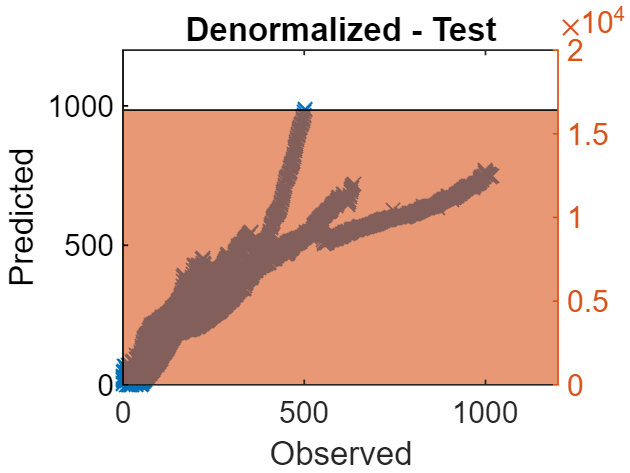

(Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2);   % Mean Squared Error
RMSE_trainValid_IcVdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcVdRul = 101.5712


RMSE_test_IcVdRul = sqrt(mean((Y_test_RUL - Yfit_test_IcVdRul).^2))

RMSE_test_IcVdRul = 95.3056

Y_test_RUL - Yfit_test_IcVdRul

ans =  -108.0915
 -102.8434
 -101.0308
  -99.7789
  -99.6714
  -97.9367
  -97.4970
  -96.8674
  -94.7319
  -93.8679


Y_test_diff_IcVdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul))

Y_test_diff_IcVdRul = 1.0e+03 *

    0.3160   -0.1081
    0.3150   -0.1028
    0.3140   -0.1010
    0.3130   -0.0998
    0.3120   -0.0997
    0.3110   -0.0979
    0.3100   -0.0975
    0.3090   -0.0969
    0.3080   -0.0947
    0.3070   -0.0939



Y_test_diff_percentage_IcVdRul = abs(Y_test_RUL-Yfit_test_IcVdRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcVdRul = 1.0e+03 *

    0.0342
    0.0326
    0.0322
    0.0319
    0.0319
    0.0315
    0.0315
    0.0313
    0.0308
    0.0306


Y_test_diff_percentage_avg_IcVdRul = sum(Y_test_diff_percentage_IcVdRul)/length(Y_test_diff_percentage_IcVdRul)

Y_test_diff_percentage_avg_IcVdRul = 59.6416

Y_trainValid_diff_IcVdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcVdRul))

Y_trainValid_diff_IcVdRul = 1.0e+03 *

    0.4280   -0.1052
    0.4270   -0.1277
    0.4260   -0.1276
    0.4250   -0.1132
    0.4240   -0.1164
    0.4230   -0.1259
    0.4220   -0.1102
    0.4210   -0.1211
    0.4200   -0.1001
    0.4190   -0.1010


Y_trainValid_diff_percentage_IcVdRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcVdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcVdRul = 1.0e+03 *

    0.0246
    0.0299
    0.0299
    0.0266
    0.0275
    0.0298
    0.0261
    0.0288
    0.0238
    0.0241


Y_trainValid_diff_percentage_avg_IcVdRul = sum(Y_trainValid_diff_percentage_IcVdRul)/length(Y_trainValid_diff_percentage_IcVdRul)

Y_trainValid_diff_percentage_avg_IcVdRul = 62.4392

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul),Y_test_diff_percentage_IcVdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160   -0.1081    0.0342
    0.0020    0.3150   -0.1028    0.0326
    0.0030    0.3140   -0.1010    0.0322
    0.0040    0.3130   -0.0998    0.0319
    0.0050    0.3120   -0.0997    0.0319
    0.0060    0.3110   -0.0979    0.0315
    0.0070    0.3100   -0.0975    0.0315
    0.0080    0.3090   -0.0969    0.0313
    0.0090    0.3080   -0.0947    0.0308
    0.0100    0.3070   -0.0939    0.0306


result_mdl_Fnn_IcVdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul),Y_test_diff_percentage_IcVdRul);
result_mdl_Fnn_IcVdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn_IcVdRul

result_mdl_Fnn_IcVdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -108.09    34.206 
       2       315    -102.84    32.649 
       3       314    -101.03    32.175 
       4       313    -99.779    31.878 
       5       312    -99.671    31.946 
       6       311    -97.937    31.491 
       7       310    -97.497    31.451 
       8       309    -96.867    31.349 
       9       308    -94.732    30.757 
      10       307    -93.868    30.576 
      11       306    -94.648    30.931 
      12       305    -93.375    30.615 
      13       304    -92.614    30.465 
      14       303    -101.67    33.556 
      15       302    -104.19    34.499 
      16       301     -94.84    31.508 


result_mdl_Fnn_IcVdRul_summary = table(RMSE_test_IcVdRul,Y_test_diff_percentage_avg_IcVdRul);
result_mdl_Fnn_IcVdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_IcVdRul_summary 

result_mdl_Fnn_IcVdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    95.306      59.642  


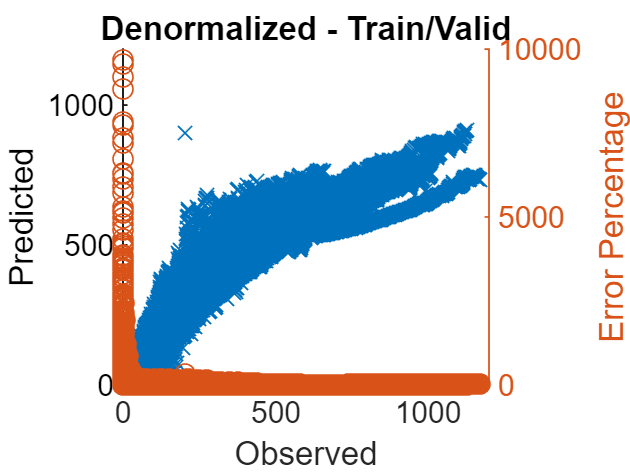


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcVdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcVdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcVdRul

RMSE_test_IcVdRul = 95.3056

Y_trainValid_diff_percentage_avg_IcVdRul

Y_trainValid_diff_percentage_avg_IcVdRul = 62.4392

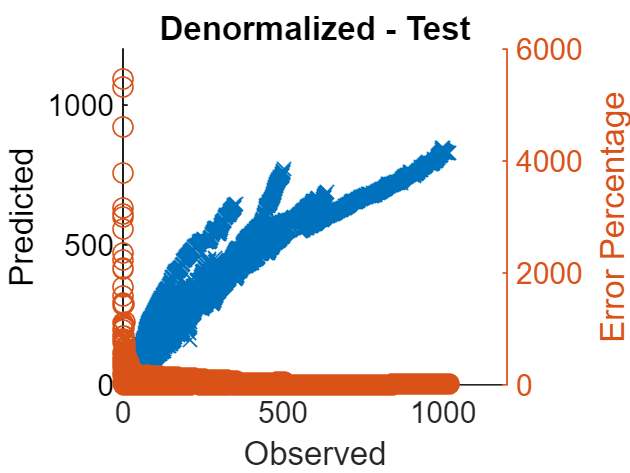


figure
hold on
plot(Y_test_RUL,Yfit_test_IcVdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcVdRul,'o');

hold off
title 'Denormalized - Test'

mdl_Fnn_IcVdRul

mdl_Fnn_IcVdRul =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1681
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

mdl_Fnn_IcVdRul.IW

ans = 2×1 cell array
    {40×40 double}
    { 0×0  double}


mdl_Fnn_IcVdRul.LW

ans = 2×2 cell array
    {0×0 double                                                                                                                                                                                                                                                                                                     }    {0×0 double}
    {[-0.1678 0.8029 -0.5492 -0.8361 -0.5223 -0.1025 0.5750 0.0454 0.1467 0.2489 -0.2682 -0.0884 0.1998 -0.3289 -0.2447 0.3932 -0.1501 -0.0408 -0.4961 0.3648 0.2865 0.0187 -0.7083 0.6509 -0.1423 0.7483 0.3504 -0.2684 -0.2068 -0.6042 0.2786 -0.6767 0.6711 -0.7403 -0.7998 0.5773 -0.8872 0.7867 0.3601 -0.7702]}    {0×0 double}


mdl_Fnn_IcVdRul.b

ans = 2×1 cell array
    {40×1 double}
    {[  -0.1416]}



cell2mat(mdl_Fnn_IcVdRul.IW(1,1))

ans =     0.2909    0.1784    0.1521    0.0682    0.1421   -0.2410   -0.2246   -0.4171   -0.3421    0.0870   -0.2576   -0.0399    0.0399    0.2889    0.0174   -0.3615   -0.3223   -0.0187    0.4282    0.2211    0.0690   -0.3097    0.2672   -0.0890    0.0085   -0.2158    0.0271    0.4178    0.3579    0.3085    0.3557    0.2634   -0.1964    0.2455   -0.0574   -0.2779   -0.0692    0.0685   -0.0847   -0.3485
    0.0438    0.3504    0.1961   -0.0356   -0.1911   -0.2611   -0.0094   -0.0420    0.1209    0.2810   -0.3458   -0.1086   -0.2117   -0.1801    0.2541    0.1261    0.0082   -0.0994    0.0293    0.3696   -0.0825    0.3282    0.2919   -0.3106    0.0100   -0.0918   -0.3432   -0.3959   -0.3154    0.3607    0.2108   -0.3891    0.3127   -0.2745    0.0317   -0.0982    0.3910    0.3512   -0.2950   -0.0130
    0.2423    0.0042   -0.2984   -0.3050   -0.3325   -0.3626   -0.2771    0.2312   -0.2641   -0.1635    0.1944   -0.2790    0.0550   -0.2028   -0.3599   -0.1569    0.2811   -0.3736    0.1066  

cell2mat(mdl_Fnn_IcVdRul.LW(2,1))

ans =    -0.1678    0.8029   -0.5492   -0.8361   -0.5223   -0.1025    0.5750    0.0454    0.1467    0.2489   -0.2682   -0.0884    0.1998   -0.3289   -0.2447    0.3932   -0.1501   -0.0408   -0.4961    0.3648    0.2865    0.0187   -0.7083    0.6509   -0.1423    0.7483    0.3504   -0.2684   -0.2068   -0.6042    0.2786   -0.6767    0.6711   -0.7403   -0.7998    0.5773   -0.8872    0.7867    0.3601   -0.7702


cell2mat(mdl_Fnn_IcVdRul.b(1,1))

ans =    -1.5485
   -1.4702
   -1.3660
    1.2955
    1.2441
   -1.1381
    1.0782
    0.9751
   -0.9379
   -0.8723


# Fnn IcVdTd_RUL

yfit_trainValid_IcVdTdRul = mdl_Fnn_IcVdTdRul(xnorm_IcVdTd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_IcVdTdRul'

ans =     0.3786    0.3856    0.3721    0.3741    0.3780    0.3782    0.3659    0.3641    0.3581    0.3512    0.3638    0.3612    0.3563    0.3559    0.3514    0.3474    0.3505    0.3362    0.3424    0.3536    0.3580    0.3495    0.3988    0.3360    0.3278    0.3158    0.3751    0.3766    0.3880    0.3752    0.3755    0.3702    0.3693    0.3679    0.3653    0.3709    0.3639    0.3626    0.3668    0.3740    0.3599    0.3924    0.3943    0.3611    0.3875    0.3620    0.3503    0.3494    0.3589    0.3607


yfit_test_IcVdTdRul = mdl_Fnn_IcVdTdRul(xnorm_IcVdTd( idxTestAll, :)')';
yfit_test_IcVdTdRul'

ans =     0.3177    0.3126    0.3080    0.2921    0.2799    0.2833    0.2754    0.2820    0.2672    0.2658    0.2639    0.2433    0.2402    0.2447    0.2509    0.3317    0.3278    0.3262    0.3451    0.3381    0.3279    0.3338    0.3429    0.3632    0.3462    0.3480    0.3639    0.3487    0.3278    0.3132    0.3031    0.3118    0.3076    0.3044    0.2956    0.2931    0.2980    0.2918    0.2884    0.2879    0.2816    0.2819    0.2849    0.2806    0.2728    0.2743    0.2694    0.2871    0.2648    0.2704



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_IcVdTdRul = yfit_trainValid_IcVdTdRul * yrate_RUL + ymin_RUL;
Yfit_test_IcVdTdRul = yfit_test_IcVdTdRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_IcVdTd_RUL * yrate_IcVdTd_RUL + ymin_IcVdTd_RUL;


MAE_IcVdTdRul = mean(abs(Yfit_trainValid_IcVdTdRul-Y_trainValid_RUL))

MAE_IcVdTdRul = 46.2359

adjMAE_IcVdTdRul = MAE_IcVdTdRul/range(Y_trainValid_RUL)

adjMAE_IcVdTdRul = 0.0395

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul)'    % Errors

ans = 1×38367
  -15.9711  -25.1921  -10.4046  -13.6996  -19.2658  -20.4733   -7.1061   -5.9482    0.0544    7.1365   -8.5995   -6.5521   -1.9134   -2.4128    1.8879    5.4889    0.8997   16.6625    8.3572   -5.7283  -11.9104   -2.9044  -61.5867   10.8693   19.4725   32.4720  -37.8574  -40.5884  -54.9067  -41.0041


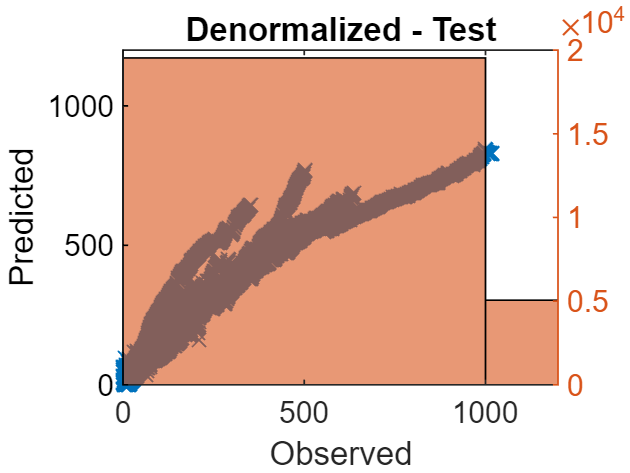

(Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2);   % Mean Squared Error
RMSE_trainValid_IcVdTdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcVdTdRul = 67.5725


RMSE_test_IcVdTdRul = sqrt(mean((Y_test_RUL - Yfit_test_IcVdTdRul).^2))

RMSE_test_IcVdTdRul = 113.4384

Y_test_RUL - Yfit_test_IcVdTdRul

ans = 4488×1
  -56.7450
  -51.7002
  -47.3263
  -29.8040
  -16.4716
  -21.5182
  -13.2531
  -21.9260
   -5.6466
   -5.0071


Y_test_diff_IcVdTdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul))

Y_test_diff_IcVdTdRul = 4488×2
  316.0000  -56.7450
  315.0000  -51.7002
  314.0000  -47.3263
  313.0000  -29.8040
  312.0000  -16.4716
  311.0000  -21.5182
  310.0000  -13.2531
  309.0000  -21.9260
  308.0000   -5.6466
  307.0000   -5.0071


Y_test_diff_percentage_IcVdTdRul = abs(Y_test_RUL-Yfit_test_IcVdTdRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcVdTdRul = 4488×1
   17.9573
   16.4128
   15.0721
    9.5221
    5.2794
    6.9190
    4.2752
    7.0958
    1.8333
    1.6310


Y_test_diff_percentage_avg_IcVdTdRul = sum(Y_test_diff_percentage_IcVdTdRul)/length(Y_test_diff_percentage_IcVdTdRul)

Y_test_diff_percentage_avg_IcVdTdRul = 60.9969

Y_trainValid_diff_IcVdTdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcVdTdRul))

Y_trainValid_diff_IcVdTdRul = 38367×2
  428.0000  -15.9711
  427.0000  -25.1921
  426.0000  -10.4046
  425.0000  -13.6996
  424.0000  -19.2658
  423.0000  -20.4733
  422.0000   -7.1061
  421.0000   -5.9482
  420.0000    0.0544
  419.0000    7.1365


Y_trainValid_diff_percentage_IcVdTdRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcVdTdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcVdTdRul = 38367×1
    3.7316
    5.8998
    2.4424
    3.2234
    4.5438
    4.8400
    1.6839
    1.4129
    0.0130
    1.7032


Y_trainValid_diff_percentage_avg_IcVdTdRul = sum(Y_trainValid_diff_percentage_IcVdTdRul)/length(Y_trainValid_diff_percentage_IcVdTdRul)

Y_trainValid_diff_percentage_avg_IcVdTdRul = 49.6200

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul),Y_test_diff_percentage_IcVdTdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000  316.0000  -56.7450   17.9573
    2.0000  315.0000  -51.7002   16.4128
    3.0000  314.0000  -47.3263   15.0721
    4.0000  313.0000  -29.8040    9.5221
    5.0000  312.0000  -16.4716    5.2794
    6.0000  311.0000  -21.5182    6.9190
    7.0000  310.0000  -13.2531    4.2752
    8.0000  309.0000  -21.9260    7.0958
    9.0000  308.0000   -5.6466    1.8333
   10.0000  307.0000   -5.0071    1.6310


result_mdl_Fnn_IcVdTdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul),Y_test_diff_percentage_IcVdTdRul);
result_mdl_Fnn_IcVdTdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn_IcVdTdRul

result_mdl_Fnn_IcVdTdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -56.745    17.957 
       2       315      -51.7    16.413 
       3       314    -47.326    15.072 
       4       313    -29.804    9.5221 
       5       312    -16.472    5.2794 
       6       311    -21.518     6.919 
       7       310    -13.253    4.2752 
       8       309    -21.926    7.0958 
       9       308    -5.6466    1.8333 
      10       307    -5.0071     1.631 
      11       306    -3.7357    1.2208 
      12       305     19.293    6.3255 
      13       304     21.923    7.2116 
      14       303     15.677    5.1739 
      15       302     7.4905    2.4803 
      16       301    -88.126    29.278 


result_mdl_Fnn_IcVdTdRul_summary = table(RMSE_test_IcVdTdRul,Y_test_diff_percentage_avg_IcVdTdRul);
result_mdl_Fnn_IcVdTdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_IcVdTdRul_summary 

result_mdl_Fnn_IcVdTdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    113.44      60.997  


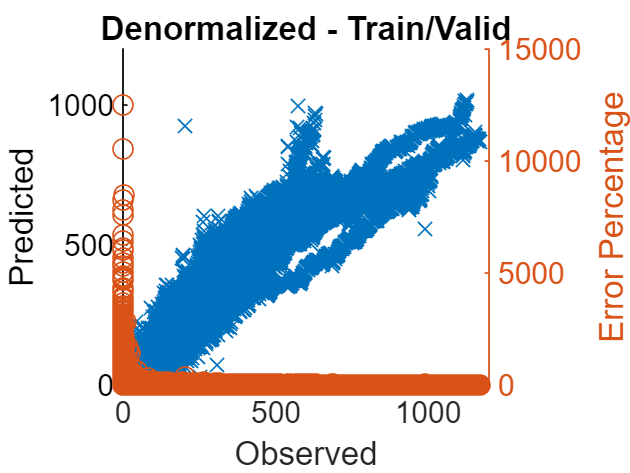


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcVdTdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcVdTdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcVdTdRul

RMSE_test_IcVdTdRul = 113.4384

Y_trainValid_diff_percentage_avg_IcVdTdRul

Y_trainValid_diff_percentage_avg_IcVdTdRul = 49.6200

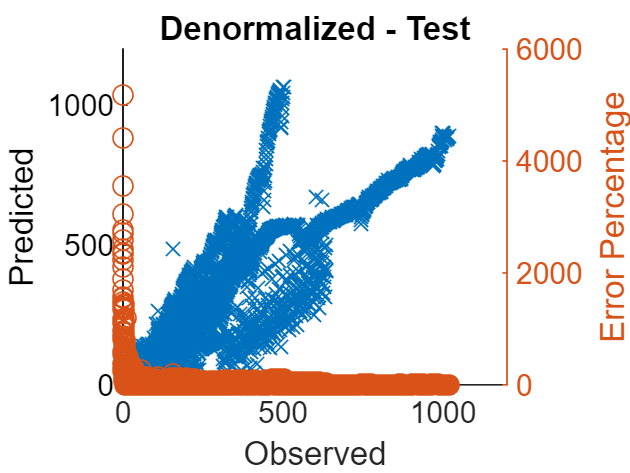


figure
hold on
plot(Y_test_RUL,Yfit_test_IcVdTdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcVdTdRul,'o');

hold off
title 'Denormalized - Test'

# Fnn3 Ic_RUL

yfit_trainValid_IcRul = mdl_Fnn3_IcRul(xnorm_Ic([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_IcRul'

ans = 1×38367
    0.3819    0.5733    0.5715    0.4695    0.4552    0.5594    0.4357    0.5526    0.3845    0.3826    0.4648    0.5489    0.5515    0.4099    0.3865    0.5417    0.5405    0.3584    0.5356    0.5384    0.5456    0.5429    0.3417    0.5415    0.5321    0.5261    0.3529    0.5162    0.3799    0.5141


yfit_test_IcRul = mdl_Fnn3_IcRul(xnorm_Ic( idxTestAll, :)')';
yfit_test_IcRul'

ans = 1×4488
    0.3356    0.3321    0.3320    0.3301    0.3292    0.3268    0.3264    0.3255    0.3235    0.3222    0.3210    0.3185    0.3171    0.3170    0.3170    0.3156    0.3142    0.3138    0.3502    0.3486    0.3106    0.3121    0.3131    0.3509    0.3139    0.3135    0.3494    0.3107    0.3086    0.3054



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_IcRul = yfit_trainValid_IcRul * yrate_RUL + ymin_RUL;
Yfit_test_IcRul = yfit_test_IcRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Ic_RUL * yrate_Ic_RUL + ymin_Ic_RUL;


MAE_IcRul = mean(abs(Yfit_trainValid_IcRul-Y_trainValid_RUL))

MAE_IcRul = 70.5765

adjMAE_IcRul = MAE_IcRul/range(Y_trainValid_RUL)

adjMAE_IcRul = 0.0603

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcRul)'    % Errors

ans = 1×38367
  -19.8093 -244.7777 -243.6213 -125.2628 -109.5501 -232.4840  -88.7383 -226.5754  -30.8809  -29.6767 -126.8582 -226.2167 -230.3048  -65.6206  -39.2296 -221.7388 -221.4384   -9.3003 -217.6596 -221.9314 -231.3829 -229.1757    5.2098 -229.5663 -219.5041 -213.5324  -11.9219 -203.8965  -45.4851 -203.4662


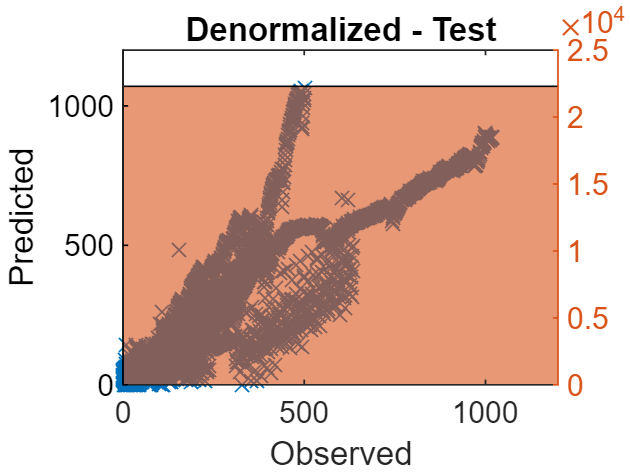

(Y_trainValid_RUL - Yfit_trainValid_IcRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2);   % Mean Squared Error
RMSE_trainValid_IcRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcRul = 105.5202


RMSE_test_IcRul = sqrt(mean((Y_test_RUL - Yfit_test_IcRul).^2))

RMSE_test_IcRul = 99.5442

Y_test_RUL - Yfit_test_IcRul

ans = 4488×1
  -77.6586
  -74.5644
  -75.4193
  -74.1675
  -74.1650
  -72.3885
  -72.9044
  -72.8008
  -71.4749
  -70.9918


Y_test_diff_IcRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul))

Y_test_diff_IcRul = 4488×2
  316.0000  -77.6586
  315.0000  -74.5644
  314.0000  -75.4193
  313.0000  -74.1675
  312.0000  -74.1650
  311.0000  -72.3885
  310.0000  -72.9044
  309.0000  -72.8008
  308.0000  -71.4749
  307.0000  -70.9918


Y_test_diff_percentage_IcRul = abs(Y_test_RUL-Yfit_test_IcRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcRul = 4488×1
   24.5755
   23.6712
   24.0189
   23.6957
   23.7708
   23.2761
   23.5176
   23.5601
   23.2061
   23.1244


Y_test_diff_percentage_avg_IcRul = sum(Y_test_diff_percentage_IcRul)/length(Y_test_diff_percentage_IcRul)

Y_test_diff_percentage_avg_IcRul = 45.0183

Y_trainValid_diff_IcRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcRul))

Y_trainValid_diff_IcRul = 38367×2
  428.0000  -19.8093
  427.0000 -244.7777
  426.0000 -243.6213
  425.0000 -125.2628
  424.0000 -109.5501
  423.0000 -232.4840
  422.0000  -88.7383
  421.0000 -226.5754
  420.0000  -30.8809
  419.0000  -29.6767


Y_trainValid_diff_percentage_IcRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcRul = 38367×1
    4.6284
   57.3250
   57.1881
   29.4736
   25.8373
   54.9608
   21.0280
   53.8184
    7.3526
    7.0827


Y_trainValid_diff_percentage_avg_IcRul = sum(Y_trainValid_diff_percentage_IcRul)/length(Y_trainValid_diff_percentage_IcRul)

Y_trainValid_diff_percentage_avg_IcRul = 42.3873

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul),Y_test_diff_percentage_IcRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000  316.0000  -77.6586   24.5755
    2.0000  315.0000  -74.5644   23.6712
    3.0000  314.0000  -75.4193   24.0189
    4.0000  313.0000  -74.1675   23.6957
    5.0000  312.0000  -74.1650   23.7708
    6.0000  311.0000  -72.3885   23.2761
    7.0000  310.0000  -72.9044   23.5176
    8.0000  309.0000  -72.8008   23.5601
    9.0000  308.0000  -71.4749   23.2061
   10.0000  307.0000  -70.9918   23.1244


result_mdl_Fnn3_IcRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcRul),Y_test_diff_percentage_IcRul);
result_mdl_Fnn3_IcRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn3_IcRul

result_mdl_Fnn3_IcRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -77.659    24.575 
       2       315    -74.564    23.671 
       3       314    -75.419    24.019 
       4       313    -74.168    23.696 
       5       312    -74.165    23.771 
       6       311    -72.389    23.276 
       7       310    -72.904    23.518 
       8       309    -72.801     23.56 
       9       308    -71.475    23.206 
      10       307    -70.992    23.124 
      11       306    -70.616    23.077 
      12       305    -68.601    22.492 
      13       304    -68.061    22.389 
      14       303    -68.835    22.718 
      15       302    -69.909    23.149 
      16       301    -69.265    23.012 


result_mdl_Fnn3_IcRul_summary = table(RMSE_test_IcRul,Y_test_diff_percentage_avg_IcRul);
result_mdl_Fnn3_IcRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_IcRul_summary 

result_mdl_Fnn3_IcRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    99.544      45.018  


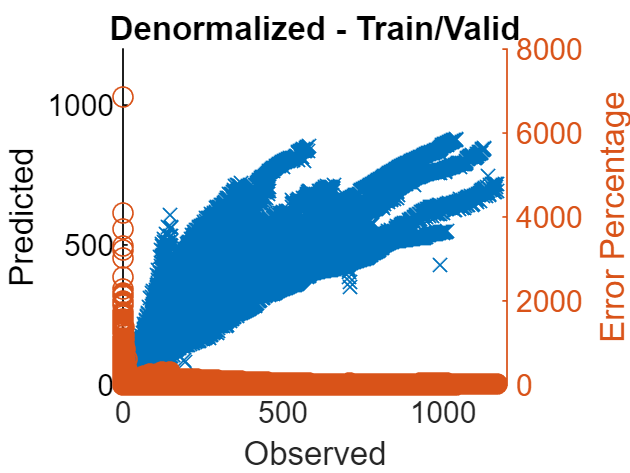


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcRul

RMSE_test_IcRul = 99.5442

Y_trainValid_diff_percentage_avg_IcRul

Y_trainValid_diff_percentage_avg_IcRul = 42.3873


figure
hold on
plot(Y_test_RUL,Yfit_test_IcRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcRul,'o');

hold off
title 'Denormalized - Test'


# Fnn3 Vd_RUL

yfit_trainValid_VdRul = mdl_Fnn3_VdRul(xnorm_Vd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_VdRul'

ans = 1×38367
    0.4238    0.4233    0.4210    0.4176    0.4221    0.4205    0.4166    0.4145    0.4120    0.4129    0.4124    0.4171    0.4155    0.4121    0.4100    0.4108    0.4114    0.4082    0.4096    0.4159    0.4257    0.4258    0.4215    0.4175    0.4139    0.4070    0.4035    0.4021    0.4032    0.4025


yfit_test_VdRul = mdl_Fnn3_VdRul(xnorm_Vd( idxTestAll, :)')';
yfit_test_VdRul'

ans = 1×4488
    0.4058    0.4001    0.3972    0.3952    0.3931    0.3914    0.3903    0.3890    0.3863    0.3843    0.3848    0.3816    0.3803    0.3887    0.3903    0.3793    0.3744    0.3747    0.3724    0.3673    0.3762    0.3944    0.4081    0.4168    0.4206    0.4230    0.4222    0.4202    0.4015    0.3717



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_VdRul = yfit_trainValid_VdRul * yrate_RUL + ymin_RUL;
Yfit_test_VdRul = yfit_test_VdRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Vd_RUL * yrate_Vd_RUL + ymin_Vd_RUL;


MAE_VdRul = mean(abs(Yfit_trainValid_VdRul-Y_trainValid_RUL))

MAE_VdRul = 70.5766

adjMAE_VdRul = MAE_VdRul/range(Y_trainValid_RUL)

adjMAE_VdRul = 0.0603

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdRul)'    % Errors

ans = 1×38367
  -68.8308  -69.2368  -67.5808  -64.5726  -70.9137  -69.9583  -66.3997  -65.0165  -63.0287  -65.0405  -65.4863  -71.9829  -71.0992  -68.1937  -66.7572  -68.6765  -70.3150  -67.6346  -70.2387  -78.6314  -91.1210  -92.1489  -88.1139  -84.5105  -81.2710  -74.1405  -71.1407  -70.4031  -72.7863  -72.9247


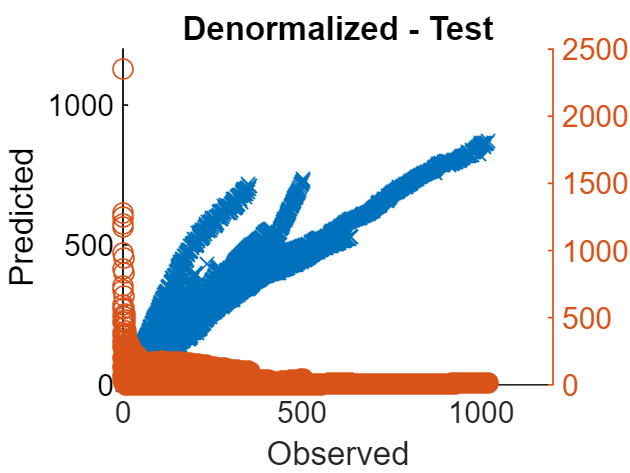

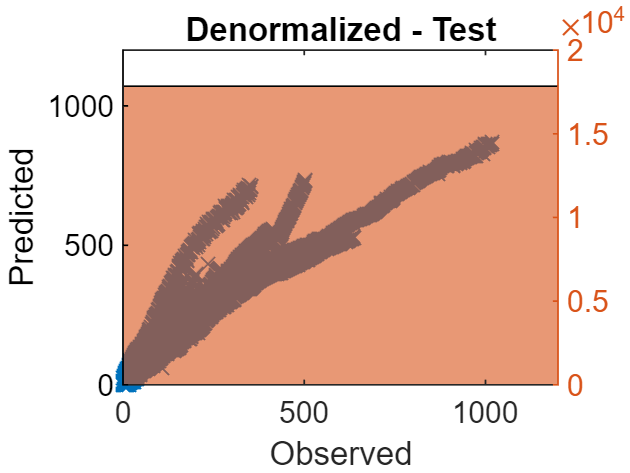

(Y_trainValid_RUL - Yfit_trainValid_VdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2);   % Mean Squared Error
RMSE_trainValid_VdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdRul = 98.0787


RMSE_test_VdRul = sqrt(mean((Y_test_RUL - Yfit_test_VdRul).^2))

RMSE_test_VdRul = 101.9828

Y_test_RUL - Yfit_test_VdRul

ans = 4488×1
 -159.7298
 -154.1496
 -151.7150
 -150.3709
 -148.9658
 -147.9392
 -147.6050
 -147.1537
 -144.9676
 -143.6126


Y_test_diff_VdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul))

Y_test_diff_VdRul = 4488×2
  316.0000 -159.7298
  315.0000 -154.1496
  314.0000 -151.7150
  313.0000 -150.3709
  312.0000 -148.9658
  311.0000 -147.9392
  310.0000 -147.6050
  309.0000 -147.1537
  308.0000 -144.9676
  307.0000 -143.6126


Y_test_diff_percentage_VdRul = abs(Y_test_RUL-Yfit_test_VdRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdRul = 4488×1
   50.5474
   48.9364
   48.3169
   48.0418
   47.7454
   47.5689
   47.6145
   47.6225
   47.0674
   46.7793


Y_test_diff_percentage_avg_VdRul = sum(Y_test_diff_percentage_VdRul)/length(Y_test_diff_percentage_VdRul)

Y_test_diff_percentage_avg_VdRul = 74.2210

Y_trainValid_diff_VdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdRul))

Y_trainValid_diff_VdRul = 38367×2
  428.0000  -68.8308
  427.0000  -69.2368
  426.0000  -67.5808
  425.0000  -64.5726
  424.0000  -70.9137
  423.0000  -69.9583
  422.0000  -66.3997
  421.0000  -65.0165
  420.0000  -63.0287
  419.0000  -65.0405


Y_trainValid_diff_percentage_VdRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdRul = 38367×1
   16.0820
   16.2147
   15.8640
   15.1936
   16.7249
   16.5386
   15.7345
   15.4433
   15.0068
   15.5228


Y_trainValid_diff_percentage_avg_VdRul = sum(Y_trainValid_diff_percentage_VdRul)/length(Y_trainValid_diff_percentage_VdRul)

Y_trainValid_diff_percentage_avg_VdRul = 70.6777

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul),Y_test_diff_percentage_VdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000  316.0000 -159.7298   50.5474
    2.0000  315.0000 -154.1496   48.9364
    3.0000  314.0000 -151.7150   48.3169
    4.0000  313.0000 -150.3709   48.0418
    5.0000  312.0000 -148.9658   47.7454
    6.0000  311.0000 -147.9392   47.5689
    7.0000  310.0000 -147.6050   47.6145
    8.0000  309.0000 -147.1537   47.6225
    9.0000  308.0000 -144.9676   47.0674
   10.0000  307.0000 -143.6126   46.7793


result_mdl_Fnn3_VdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_VdRul),Y_test_diff_percentage_VdRul);
result_mdl_Fnn3_VdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn3_VdRul

result_mdl_Fnn3_VdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -159.73    50.547 
       2       315    -154.15    48.936 
       3       314    -151.72    48.317 
       4       313    -150.37    48.042 
       5       312    -148.97    47.745 
       6       311    -147.94    47.569 
       7       310     -147.6    47.615 
       8       309    -147.15    47.623 
       9       308    -144.97    47.067 
      10       307    -143.61    46.779 
      11       306    -145.16    47.438 
      12       305    -142.46    46.709 
      13       304    -141.95    46.695 
      14       303    -152.81    50.431 
      15       302    -155.68    51.549 
      16       301    -143.79    47.771 


result_mdl_Fnn3_VdRul_summary = table(RMSE_test_VdRul,Y_test_diff_percentage_avg_VdRul);
result_mdl_Fnn3_VdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_VdRul_summary 

result_mdl_Fnn3_VdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    101.98      74.221  


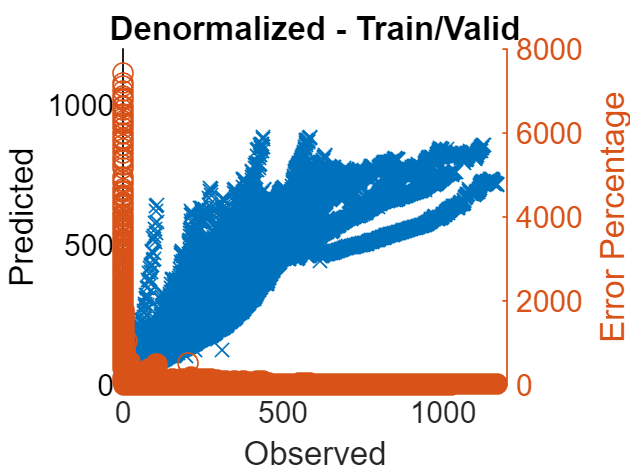


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdRul

RMSE_test_VdRul = 101.9828

Y_trainValid_diff_percentage_avg_VdRul

Y_trainValid_diff_percentage_avg_VdRul = 70.6777

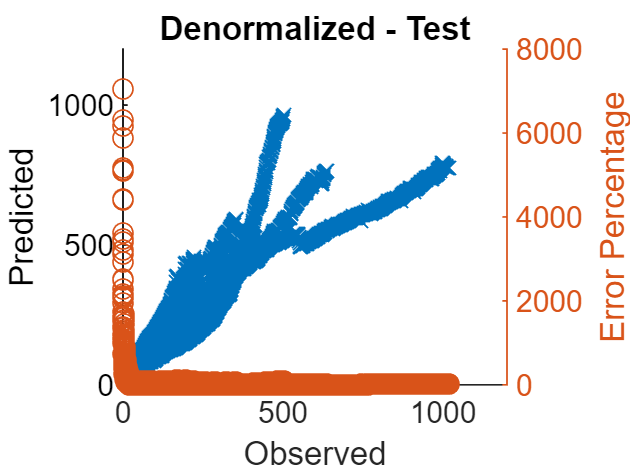


figure
hold on
plot(Y_test_RUL,Yfit_test_VdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_VdRul,'o');

hold off
title 'Denormalized - Test'

# Fnn3 IcVd_RUL

yfit_trainValid_IcVdRul = mdl_Fnn3_IcVdRul(xnorm_IcVd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_IcVdRul'

ans = 1×38367
    0.3912    0.4178    0.4148    0.4013    0.4004    0.4109    0.3906    0.4060    0.3808    0.3787    0.3908    0.4062    0.4074    0.3796    0.3770    0.3994    0.3961    0.3662    0.3956    0.4083    0.4180    0.4183    0.3883    0.4100    0.3997    0.3926    0.3661    0.3837    0.3815    0.3837


yfit_test_IcVdRul = mdl_Fnn3_IcVdRul(xnorm_IcVd( idxTestAll, :)')';
yfit_test_IcVdRul'

ans = 1×4488
    0.2632    0.2621    0.2614    0.2596    0.2587    0.2586    0.2585    0.2594    0.2580    0.2574    0.2571    0.2550    0.2550    0.2570    0.2570    0.2528    0.2535    0.2524    0.2715    0.2688    0.2539    0.2551    0.2584    0.2790    0.2620    0.2598    0.2789    0.2581    0.2538    0.2493



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_IcVdRul = yfit_trainValid_IcVdRul * yrate_RUL + ymin_RUL;
Yfit_test_IcVdRul = yfit_test_IcVdRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_IcVd_RUL * yrate_IcVd_RUL + ymin_IcVd_RUL;


MAE_IcVdRul = mean(abs(Yfit_trainValid_IcVdRul-Y_trainValid_RUL))

MAE_IcVdRul = 58.8597

adjMAE_IcVdRul = MAE_IcVdRul/range(Y_trainValid_RUL)

adjMAE_IcVdRul = 0.0503

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcVdRul)'    % Errors

ans = 1×38367
  -30.6837  -62.8815  -60.2818  -45.4758  -45.4747  -58.7923  -36.0412  -55.0755  -26.5159  -25.0825  -40.2853  -59.2311  -61.6492  -30.1828  -28.1418  -55.2938  -52.4277  -18.4228  -53.8259  -69.6997  -82.0584  -83.3531  -49.2964  -75.7092  -64.6715  -57.3167  -27.3571  -48.9117  -47.3512  -50.9865


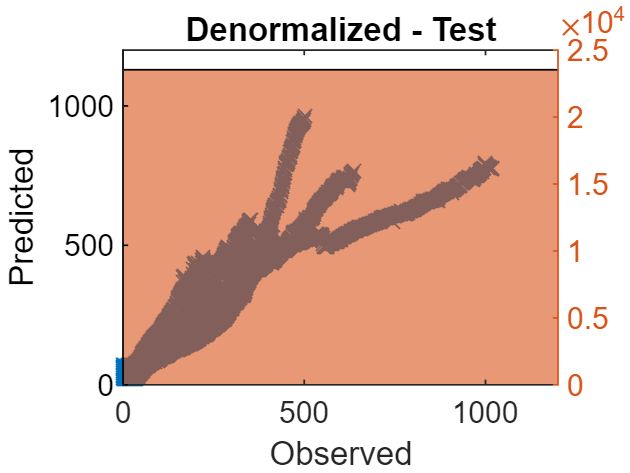

(Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2);   % Mean Squared Error
RMSE_trainValid_IcVdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcVdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcVdRul = 84.6502


RMSE_test_IcVdRul = sqrt(mean((Y_test_RUL - Yfit_test_IcVdRul).^2))

RMSE_test_IcVdRul = 97.2759

Y_test_RUL - Yfit_test_IcVdRul

ans = 4488×1
    7.0997
    7.3803
    7.1871
    8.2253
    8.3482
    7.4546
    6.5712
    4.5428
    5.1552
    4.8274


Y_test_diff_IcVdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul))

Y_test_diff_IcVdRul = 4488×2
  316.0000    7.0997
  315.0000    7.3803
  314.0000    7.1871
  313.0000    8.2253
  312.0000    8.3482
  311.0000    7.4546
  310.0000    6.5712
  309.0000    4.5428
  308.0000    5.1552
  307.0000    4.8274



Y_test_diff_percentage_IcVdRul = abs(Y_test_RUL-Yfit_test_IcVdRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcVdRul = 4488×1
    2.2467
    2.3429
    2.2889
    2.6279
    2.6757
    2.3970
    2.1197
    1.4702
    1.6738
    1.5724


Y_test_diff_percentage_avg_IcVdRul = sum(Y_test_diff_percentage_IcVdRul)/length(Y_test_diff_percentage_IcVdRul)

Y_test_diff_percentage_avg_IcVdRul = 39.0389

Y_trainValid_diff_IcVdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcVdRul))

Y_trainValid_diff_IcVdRul = 38367×2
  428.0000  -30.6837
  427.0000  -62.8815
  426.0000  -60.2818
  425.0000  -45.4758
  424.0000  -45.4747
  423.0000  -58.7923
  422.0000  -36.0412
  421.0000  -55.0755
  420.0000  -26.5159
  419.0000  -25.0825


Y_trainValid_diff_percentage_IcVdRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcVdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcVdRul = 38367×1
    7.1691
   14.7264
   14.1507
   10.7002
   10.7252
   13.8989
    8.5406
   13.0821
    6.3133
    5.9863


Y_trainValid_diff_percentage_avg_IcVdRul = sum(Y_trainValid_diff_percentage_IcVdRul)/length(Y_trainValid_diff_percentage_IcVdRul)

Y_trainValid_diff_percentage_avg_IcVdRul = 37.0066

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul),Y_test_diff_percentage_IcVdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000  316.0000    7.0997    2.2467
    2.0000  315.0000    7.3803    2.3429
    3.0000  314.0000    7.1871    2.2889
    4.0000  313.0000    8.2253    2.6279
    5.0000  312.0000    8.3482    2.6757
    6.0000  311.0000    7.4546    2.3970
    7.0000  310.0000    6.5712    2.1197
    8.0000  309.0000    4.5428    1.4702
    9.0000  308.0000    5.1552    1.6738
   10.0000  307.0000    4.8274    1.5724


result_mdl_Fnn3_IcVdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdRul),Y_test_diff_percentage_IcVdRul);
result_mdl_Fnn3_IcVdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn3_IcVdRul

result_mdl_Fnn3_IcVdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316     7.0997     2.2467
       2       315     7.3803     2.3429
       3       314     7.1871     2.2889
       4       313     8.2253     2.6279
       5       312     8.3482     2.6757
       6       311     7.4546      2.397
       7       310     6.5712     2.1197
       8       309     4.5428     1.4702
       9       308     5.1552     1.6738
      10       307     4.8274     1.5724
      11       306      4.146     1.3549
      12       305     5.6609      1.856
      13       304     4.5963     1.5119
      14       303     1.3273    0.43805
      15       302    0.36427    0.12062
      16       301     4.2197     1.4019


result_mdl_Fnn3_IcVdRul_summary = table(RMSE_test_IcVdRul,Y_test_diff_percentage_avg_IcVdRul);
result_mdl_Fnn3_IcVdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_IcVdRul_summary 

result_mdl_Fnn3_IcVdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    97.276      39.039  


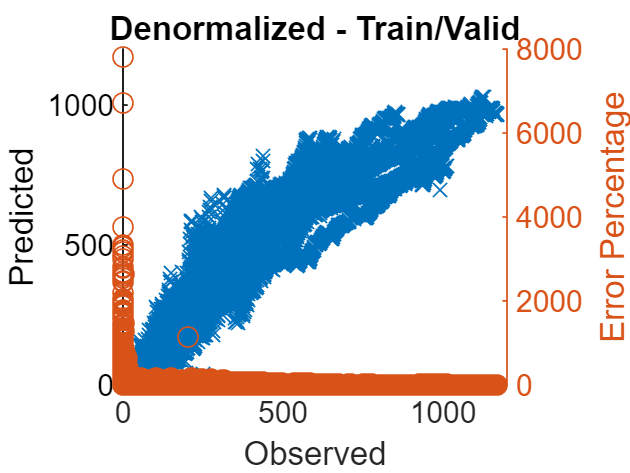


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcVdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcVdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcVdRul

RMSE_test_IcVdRul = 97.2759

Y_trainValid_diff_percentage_avg_IcVdRul

Y_trainValid_diff_percentage_avg_IcVdRul = 37.0066

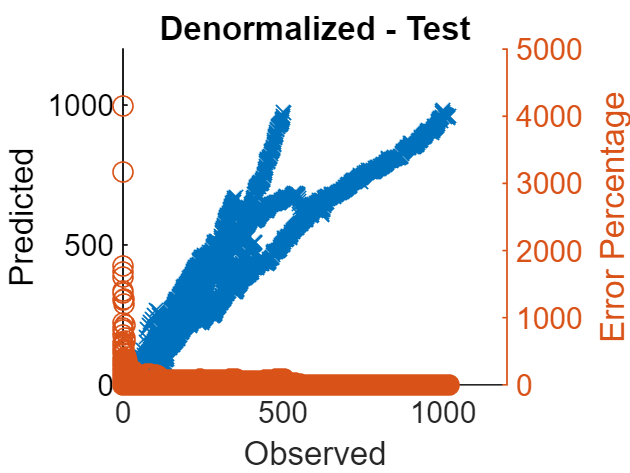


figure
hold on
plot(Y_test_RUL,Yfit_test_IcVdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcVdRul,'o');

hold off
title 'Denormalized - Test'

# Fnn3 IcVdTd_RUL

yfit_trainValid_IcVdTdRul = mdl_Fnn3_IcVdTdRul(xnorm_IcVdTd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_IcVdTdRul'

ans = 1×38367
    0.3796    0.4256    0.4132    0.3923    0.3906    0.4156    0.3793    0.4033    0.3613    0.3557    0.3805    0.4011    0.4011    0.3672    0.3568    0.3888    0.3890    0.3410    0.3796    0.3894    0.3953    0.3876    0.3829    0.3825    0.3731    0.3667    0.3684    0.4035    0.3696    0.4014


yfit_test_IcVdTdRul = mdl_Fnn3_IcVdTdRul(xnorm_IcVdTd( idxTestAll, :)')';
yfit_test_IcVdTdRul'

ans = 1×4488
    0.3157    0.3113    0.3081    0.2971    0.2903    0.2931    0.2895    0.2907    0.2797    0.2790    0.2781    0.2620    0.2620    0.2651    0.2688    0.3182    0.3142    0.3151    0.3267    0.3204    0.3181    0.3285    0.3385    0.3523    0.3456    0.3428    0.3544    0.3503    0.3274    0.3084



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_IcVdTdRul = yfit_trainValid_IcVdTdRul * yrate_RUL + ymin_RUL;
Yfit_test_IcVdTdRul = yfit_test_IcVdTdRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_IcVdTd_RUL * yrate_IcVdTd_RUL + ymin_IcVdTd_RUL;


MAE_IcVdTdRul = mean(abs(Yfit_trainValid_IcVdTdRul-Y_trainValid_RUL))

MAE_IcVdTdRul = 40.2798

adjMAE_IcVdTdRul = MAE_IcVdTdRul/range(Y_trainValid_RUL)

adjMAE_IcVdTdRul = 0.0344

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul)'    % Errors

ans = 1×38367
  -17.1151  -71.9963  -58.4571  -35.0473  -33.9608  -64.2259  -22.8239  -51.8282   -3.6644    1.8765  -28.1461  -53.2863  -54.2720  -15.5891   -4.4586  -42.9209  -44.0868   11.0050  -35.1845  -47.5879  -55.4515  -47.5445  -43.0177  -43.4824  -33.5352  -27.0773  -30.0865  -72.0715  -33.4721  -71.5840


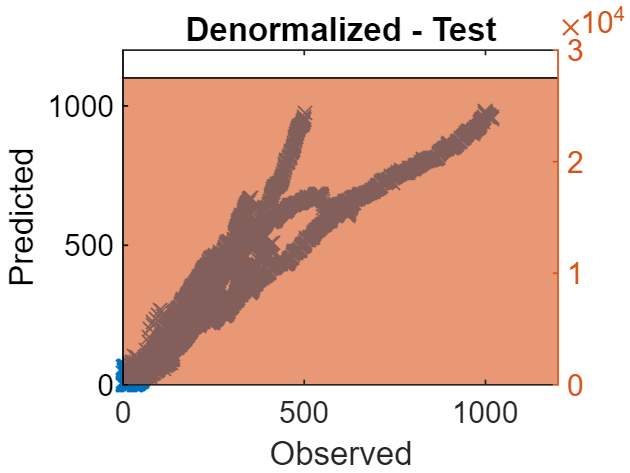

(Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2);   % Mean Squared Error
RMSE_trainValid_IcVdTdRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcVdTdRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcVdTdRul = 63.8116


RMSE_test_IcVdTdRul = sqrt(mean((Y_test_RUL - Yfit_test_IcVdTdRul).^2))

RMSE_test_IcVdTdRul = 121.0215

Y_test_RUL - Yfit_test_IcVdTdRul

ans = 4488×1
  -54.4166
  -50.2374
  -47.4360
  -35.5997
  -28.6903
  -32.9661
  -29.7566
  -32.1185
  -20.2801
  -20.4754


Y_test_diff_IcVdTdRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul))

Y_test_diff_IcVdTdRul = 4488×2
  316.0000  -54.4166
  315.0000  -50.2374
  314.0000  -47.4360
  313.0000  -35.5997
  312.0000  -28.6903
  311.0000  -32.9661
  310.0000  -29.7566
  309.0000  -32.1185
  308.0000  -20.2801
  307.0000  -20.4754


Y_test_diff_percentage_IcVdTdRul = abs(Y_test_RUL-Yfit_test_IcVdTdRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcVdTdRul = 4488×1
   17.2204
   15.9484
   15.1070
   11.3737
    9.1956
   10.6000
    9.5989
   10.3943
    6.5844
    6.6695


Y_test_diff_percentage_avg_IcVdTdRul = sum(Y_test_diff_percentage_IcVdTdRul)/length(Y_test_diff_percentage_IcVdTdRul)

Y_test_diff_percentage_avg_IcVdTdRul = 43.8036

Y_trainValid_diff_IcVdTdRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcVdTdRul))

Y_trainValid_diff_IcVdTdRul = 38367×2
  428.0000  -17.1151
  427.0000  -71.9963
  426.0000  -58.4571
  425.0000  -35.0473
  424.0000  -33.9608
  423.0000  -64.2259
  422.0000  -22.8239
  421.0000  -51.8282
  420.0000   -3.6644
  419.0000    1.8765


Y_trainValid_diff_percentage_IcVdTdRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcVdTdRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcVdTdRul = 38367×1
    3.9989
   16.8610
   13.7223
    8.2464
    8.0096
   15.1834
    5.4085
   12.3107
    0.8725
    0.4479


Y_trainValid_diff_percentage_avg_IcVdTdRul = sum(Y_trainValid_diff_percentage_IcVdTdRul)/length(Y_trainValid_diff_percentage_IcVdTdRul)

Y_trainValid_diff_percentage_avg_IcVdTdRul = 30.3892

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul),Y_test_diff_percentage_IcVdTdRul);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000  316.0000  -54.4166   17.2204
    2.0000  315.0000  -50.2374   15.9484
    3.0000  314.0000  -47.4360   15.1070
    4.0000  313.0000  -35.5997   11.3737
    5.0000  312.0000  -28.6903    9.1956
    6.0000  311.0000  -32.9661   10.6000
    7.0000  310.0000  -29.7566    9.5989
    8.0000  309.0000  -32.1185   10.3943
    9.0000  308.0000  -20.2801    6.5844
   10.0000  307.0000  -20.4754    6.6695


result_mdl_Fnn3_IcVdTdRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_IcVdTdRul),Y_test_diff_percentage_IcVdTdRul);
result_mdl_Fnn3_IcVdTdRul.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_mdl_Fnn3_IcVdTdRul

result_mdl_Fnn3_IcVdTdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -54.417      17.22
       2       315    -50.237     15.948
       3       314    -47.436     15.107
       4       313      -35.6     11.374
       5       312     -28.69     9.1956
       6       311    -32.966       10.6
       7       310    -29.757     9.5989
       8       309    -32.118     10.394
       9       308     -20.28     6.5844
      10       307    -20.475     6.6695
      11       306    -20.384     6.6615
      12       305    -2.5059    0.82162
      13       304    -3.5406     1.1647
      14       303    -8.1289     2.6828
      15       302    -13.552     4.4874
      16       301    -72.347     24.036


result_mdl_Fnn3_IcVdTdRul_summary = table(RMSE_test_IcVdTdRul,Y_test_diff_percentage_avg_IcVdTdRul);
result_mdl_Fnn3_IcVdTdRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_IcVdTdRul_summary 

result_mdl_Fnn3_IcVdTdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    121.02      43.804  


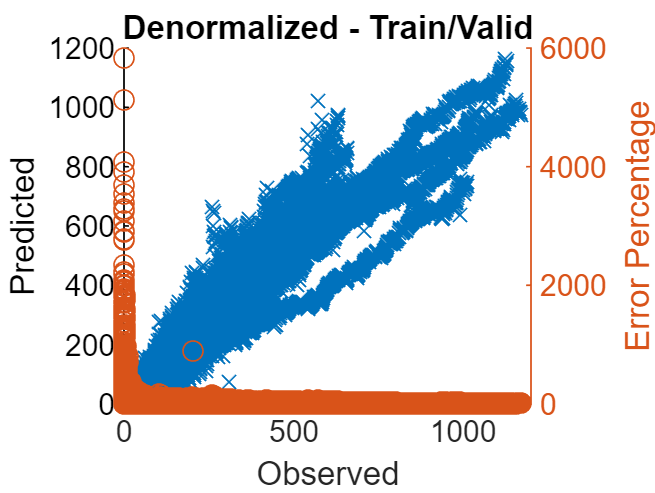


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcVdTdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcVdTdRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcVdTdRul

RMSE_test_IcVdTdRul = 121.0215

Y_trainValid_diff_percentage_avg_IcVdTdRul

Y_trainValid_diff_percentage_avg_IcVdTdRul = 30.3892

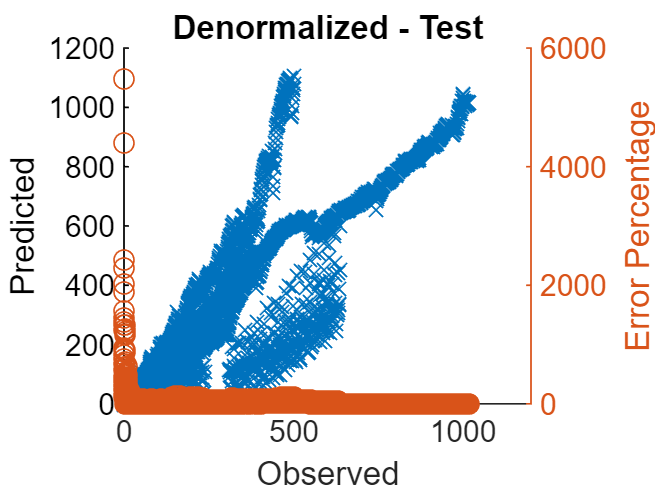


figure
hold on
plot(Y_test_RUL,Yfit_test_IcVdTdRul,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_RUL,Y_test_diff_percentage_IcVdTdRul,'o');

hold off
title 'Denormalized - Test'

# 실험결과 

result_mdl_Linear_IcRul

result_mdl_Linear_IcRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -93.861    29.703 
       2       315    -86.662    27.512 
       3       314    -87.321    27.809 
       4       313    -83.826    26.781 
       5       312    -82.767    26.528 
       6       311    -78.132    25.123 
       7       310    -77.987    25.157 
       8       309    -76.829    24.864 
       9       308    -73.308    23.801 
      10       307    -71.365    23.246 
      11       306    -69.668    22.767 
      12       305     -64.58    21.174 
      13       304    -62.586    20.588 
      14       303    -63.047    20.808 
      15       302    -64.213    21.263 
      16       301    -61.966    20.587 


result_mdl_Linear_VdRul

result_mdl_Linear_VdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -96.351    30.491 
       2       315    -102.53    32.548 
       3       314    -101.01    32.169 
       4       313      -91.9    29.361 
       5       312    -84.377    27.044 
       6       311    -91.501    29.422 
       7       310     -81.36    26.245 
       8       309    -99.361    32.156 
       9       308     -91.33    29.653 
      10       307    -94.139    30.664 
      11       306    -82.361    26.915 
      12       305    -84.971    27.859 
      13       304     -81.78    26.901 
      14       303    -92.047    30.378 
      15       302    -95.388    31.585 
      16       301    -94.502    31.396 


result_mdl_Linear_IcVdRul

result_mdl_Linear_IcVdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -79.538     25.17 
       2       315    -79.983    25.391 
       3       314    -76.594    24.393 
       4       313    -71.647     22.89 
       5       312    -63.707    20.419 
       6       311    -68.444    22.008 
       7       310    -62.418    20.135 
       8       309    -76.692    24.819 
       9       308    -68.922    22.377 
      10       307    -71.856    23.406 
      11       306    -65.296    21.339 
      12       305    -61.882    20.289 
      13       304    -61.467    20.219 
      14       303    -72.081    23.789 
      15       302     -75.41     24.97 
      16       301    -69.859    23.209 


result_mdl_Linear_IcVdTdRul

result_mdl_Linear_IcVdTdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -46.167      14.61
       2       315     -40.32       12.8
       3       314    -40.114     12.775
       4       313    -18.598     5.9419
       5       312     11.277     3.6144
       6       311     2.2412    0.72063
       7       310     17.213     5.5525
       8       309    -3.1101     1.0065
       9       308     12.151     3.9452
      10       307     16.967     5.5267
      11       306     18.661     6.0983
      12       305     55.783     18.289
      13       304     70.284      23.12
      14       303      48.14     15.888
      15       302     40.309     13.347
      16       301      -81.2     26.977


result_mdl_Fnn_IcRul

result_mdl_Fnn_IcRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -90.195    28.543 
       2       315     -84.63    26.867 
       3       314    -85.439     27.21 
       4       313    -82.757     26.44 
       5       312     -82.03    26.292 
       6       311    -78.483    25.236 
       7       310    -78.588    25.351 
       8       309     -77.68    25.139 
       9       308    -75.002    24.351 
      10       307     -73.66    23.994 
      11       306     -72.51    23.696 
      12       305    -68.321      22.4 
      13       304     -66.88        22 
      14       303     -67.38    22.238 
      15       302    -68.482    22.676 
      16       301    -66.804    22.194 


result_mdl_Fnn_VdRul

result_mdl_Fnn_VdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -135.05    42.736 
       2       315    -132.23    41.977 
       3       314    -131.34    41.829 
       4       313    -128.74     41.13 
       5       312    -128.48    41.178 
       6       311    -128.08    41.184 
       7       310    -127.71    41.196 
       8       309    -129.31    41.848 
       9       308    -127.45    41.381 
      10       307    -127.74    41.608 
      11       306    -127.91    41.799 
      12       305    -126.28    41.403 
      13       304     -126.1    41.481 
      14       303    -135.03    44.564 
      15       302    -136.75    45.281 
      16       301    -127.57    42.383 


result_mdl_Fnn_IcVdRul

result_mdl_Fnn_IcVdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -108.09    34.206 
       2       315    -102.84    32.649 
       3       314    -101.03    32.175 
       4       313    -99.779    31.878 
       5       312    -99.671    31.946 
       6       311    -97.937    31.491 
       7       310    -97.497    31.451 
       8       309    -96.867    31.349 
       9       308    -94.732    30.757 
      10       307    -93.868    30.576 
      11       306    -94.648    30.931 
      12       305    -93.375    30.615 
      13       304    -92.614    30.465 
      14       303    -101.67    33.556 
      15       302    -104.19    34.499 
      16       301     -94.84    31.508 


result_mdl_Fnn_IcVdTdRul

result_mdl_Fnn_IcVdTdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -56.745    17.957 
       2       315      -51.7    16.413 
       3       314    -47.326    15.072 
       4       313    -29.804    9.5221 
       5       312    -16.472    5.2794 
       6       311    -21.518     6.919 
       7       310    -13.253    4.2752 
       8       309    -21.926    7.0958 
       9       308    -5.6466    1.8333 
      10       307    -5.0071     1.631 
      11       306    -3.7357    1.2208 
      12       305     19.293    6.3255 
      13       304     21.923    7.2116 
      14       303     15.677    5.1739 
      15       302     7.4905    2.4803 
      16       301    -88.126    29.278 


result_mdl_Fnn3_IcRul

result_mdl_Fnn3_IcRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -77.659    24.575 
       2       315    -74.564    23.671 
       3       314    -75.419    24.019 
       4       313    -74.168    23.696 
       5       312    -74.165    23.771 
       6       311    -72.389    23.276 
       7       310    -72.904    23.518 
       8       309    -72.801     23.56 
       9       308    -71.475    23.206 
      10       307    -70.992    23.124 
      11       306    -70.616    23.077 
      12       305    -68.601    22.492 
      13       304    -68.061    22.389 
      14       303    -68.835    22.718 
      15       302    -69.909    23.149 
      16       301    -69.265    23.012 


result_mdl_Fnn3_VdRul

result_mdl_Fnn3_VdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -159.73    50.547 
       2       315    -154.15    48.936 
       3       314    -151.72    48.317 
       4       313    -150.37    48.042 
       5       312    -148.97    47.745 
       6       311    -147.94    47.569 
       7       310     -147.6    47.615 
       8       309    -147.15    47.623 
       9       308    -144.97    47.067 
      10       307    -143.61    46.779 
      11       306    -145.16    47.438 
      12       305    -142.46    46.709 
      13       304    -141.95    46.695 
      14       303    -152.81    50.431 
      15       302    -155.68    51.549 
      16       301    -143.79    47.771 


result_mdl_Fnn3_IcVdRul

result_mdl_Fnn3_IcVdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316     7.0997     2.2467
       2       315     7.3803     2.3429
       3       314     7.1871     2.2889
       4       313     8.2253     2.6279
       5       312     8.3482     2.6757
       6       311     7.4546      2.397
       7       310     6.5712     2.1197
       8       309     4.5428     1.4702
       9       308     5.1552     1.6738
      10       307     4.8274     1.5724
      11       306      4.146     1.3549
      12       305     5.6609      1.856
      13       304     4.5963     1.5119
      14       303     1.3273    0.43805
      15       302    0.36427    0.12062
      16       301     4.2197     1.4019


result_mdl_Fnn3_IcVdTdRul

result_mdl_Fnn3_IcVdTdRul = 4488×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       316    -54.417      17.22
       2       315    -50.237     15.948
       3       314    -47.436     15.107
       4       313      -35.6     11.374
       5       312     -28.69     9.1956
       6       311    -32.966       10.6
       7       310    -29.757     9.5989
       8       309    -32.118     10.394
       9       308     -20.28     6.5844
      10       307    -20.475     6.6695
      11       306    -20.384     6.6615
      12       305    -2.5059    0.82162
      13       304    -3.5406     1.1647
      14       303    -8.1289     2.6828
      15       302    -13.552     4.4874
      16       301    -72.347     24.036



result_mdl_Linear_IcRul_summary

result_mdl_Linear_IcRul_summary = 1×2 table
    RMSE     평균오차비율
    _____    __________

    123.5      94.303  


result_mdl_Linear_VdRul_summary %%%

result_mdl_Linear_VdRul_summary = 1×2 table
    RMSE     평균오차비율
    _____    __________

    95.09      57.194  


result_mdl_Linear_IcVdRul_summary

result_mdl_Linear_IcVdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    94.797      69.102  


result_mdl_Linear_IcVdTdRul_summary

result_mdl_Linear_IcVdTdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    92.431      70.184  


result_mdl_Fnn_IcRul_summary

result_mdl_Fnn_IcRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    95.219      53.273  


result_mdl_Fnn_VdRul_summary

result_mdl_Fnn_VdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    110.05      63.447  


result_mdl_Fnn_IcVdRul_summary  %%%

result_mdl_Fnn_IcVdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    95.306      59.642  


result_mdl_Fnn_IcVdTdRul_summary

result_mdl_Fnn_IcVdTdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    113.44      60.997  


result_mdl_Fnn3_IcRul_summary

result_mdl_Fnn3_IcRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    99.544      45.018  


result_mdl_Fnn3_VdRul_summary   %%%

result_mdl_Fnn3_VdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    101.98      74.221  


result_mdl_Fnn3_IcVdRul_summary

result_mdl_Fnn3_IcVdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    97.276      39.039  


result_mdl_Fnn3_IcVdTdRul_summary

result_mdl_Fnn3_IcVdTdRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    121.02      43.804  


save('ryan4_model_RUL.mat','result_mdl_Linear_IcRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Linear_VdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Linear_IcVdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Linear_IcVdTdRul' ,'-append')

save('ryan4_model_RUL.mat','result_mdl_Fnn_IcRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn_VdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn_IcVdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn_IcVdTdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_IcRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_VdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_IcVdRul' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_IcVdTdRul' ,'-append')

save('ryan4_model_RUL.mat','result_mdl_Linear_IcRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Linear_VdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Linear_IcVdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Linear_IcVdTdRul_summary' ,'-append')

save('ryan4_model_RUL.mat','result_mdl_Fnn_IcRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn_VdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn_IcVdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn_IcVdTdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_IcRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_VdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_IcVdRul_summary' ,'-append')
save('ryan4_model_RUL.mat','result_mdl_Fnn3_IcVdTdRul_summary' ,'-append')



% https://kr.mathworks.com/help/matlab/data_analysis/linear-regression.html
% https://kr.mathworks.com/matlabcentral/answers/368689-how-to-define-a-custom-equation-in-fitlm-function-for-linear-regression



# 점진적 학습 

% https://ko.d2l.ai/chapter_deep-learning-basics/linear-regression-scratch.html
% https://kr.mathworks.com/matlabcentral/answers/396721-how-to-retrain-existing-and-trained-neural-network-without-destroying-trained-content


% 실험에 사용할 테스트 데이타를 읽어 들인다.

%load('ryan4_data.mat','x_trainValid_Ic')
%load('ryan4_data.mat','x_trainValid_Vd')

%load('ryan4_data.mat','x_test_Ic_RUL')
%load('ryan4_data.mat','x_test_Vd')

% 기존 모델을 가져화 학습한다.
% 선형회구에서는 기존의 학습 데이타를 모두 가져오고 자신의 데이타를 새로 넣어주면 된다.
% 즉 모델을 update할 수 있는 함수가 matlab 없는 듯하다. 
% FNN 은 train() 함수가 있으므로 가능하다.

% matlab에서 점진적 학습을 하는 함수가 있다.
% https://kr.mathworks.com/help/stats/incrementalregressionlinear.html
% https://kr.mathworks.com/help/stats/incremental-learning-regression.html?s_tid=CRUX_lftnav



% https://kr.mathworks.com/help/stats/regressionlinear.incrementallearner.html
%IncrementalMdl_Linear_IcRul = incrementalLearner(mdl_Linear_IcRul)
%IncrementalMdl_Linear_VdRul = incrementalLearner(mdl_Linear_VdRul)

% https://kr.mathworks.com/help/stats/incrementalregressionlinear.html
% openExample('stats/ConfigureIncrementalLearningOptionsExample')
% openExample('stats/ConvertTraditionallyTrainedModelToIncrementalLearnerObjRExample')